# Data Processing - Capacity

#### 여기서는 배터리 데이타를 기반으로 사용자 패턴을 가지는 데이타를 생성하자.  그러나 어렵다.

- B7의 그래프가 이상하다. 더 낮은 SOC 까지 사용하므로 빨리 죽어야 하는데 더 오래산다.

- C rate 와 온도를 의심했으나 데이타를 보면 온도와 C rate 는 다른 배터리 5,6,7 과 같다.

- 아무래도 다른 요인이 더 있는 것 같으나 데이타에서는 확인 불가능하다.   

- 각 배터리의 초기값의 차이가 있어서 분석이 어렵다.

- 정열을 시도했으나 완만학 선형이 아니라서 어려움이 있다.

#### 전체 배터리 테이타를 모두 그려서 사용가능한 데이타를 찾자.

B5

- 기준이 되는 배터리

B6

- B5와 대비해서 cut off voltage 가 낮으므로 SOH가 빨리 줄어든다.

B7 

- 실제 그래프가 이상하다 B0007 이 가장 빨리 daed 라인에 걸쳐야 하나 초기 Capacity가 높아서 분석하기 힘들다.

- discarge voltage 는 시나리오 마다 다르며 NASA 에서는 CC 로 전류소모 2.7볼트에서 cutfoff 

- 따라서 ageing 에 따라 capacity 가 떨어지고 2.7볼트로 떨어지는 시간이 빨라진다.

- B007이 오래가는 이유 : 배터리특성. cutoff voltage 가 중요한 것이 아니라 그 시간이 중요하다. 이것을 결국 용량이다.

- 그런데 이것은 더 시간이 길다. 그러므로 B0005 보다 오래 가는 이상한 결과를 보여준다.

- 따라서 분석 대상에서 제외

 B18

- 배터리 5,6,7 과 다른 사이클 시간을 갖는다. 따라서 위 3개 배터리와 다른 조건에서 테스트가 진행되었다.

## Dataset

Data Description:

A set of four Li-ion batteries **(# 5, 6, 7 and 18**) were run through 3 different operational profiles (charge, discharge and impedance) **at room temperature (ryan - 데이타에서는 24 degree C로 표시)**. Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at a constant current (CC) level of 2A until the battery voltage fell to** 2.7V, 2.5V, 2.2V and 2.5V** for batteries 5 6 7 and 18 respectively. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 42% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).

Data Description:

A set of three Li-ion batteries **(# 33, 34 and 36)** were run through 3 different operational profiles (charge, discharge and impedance) at room temperature **(24 deg C)**. Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A **until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively.** For battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

[https://medium.com/batterybits/comparison-of-open-datasets-for-lithium-ion-battery-testing-fd0de091ca2](https://medium.com/batterybits/comparison-of-open-datasets-for-lithium-ion-battery-testing-fd0de091ca2)

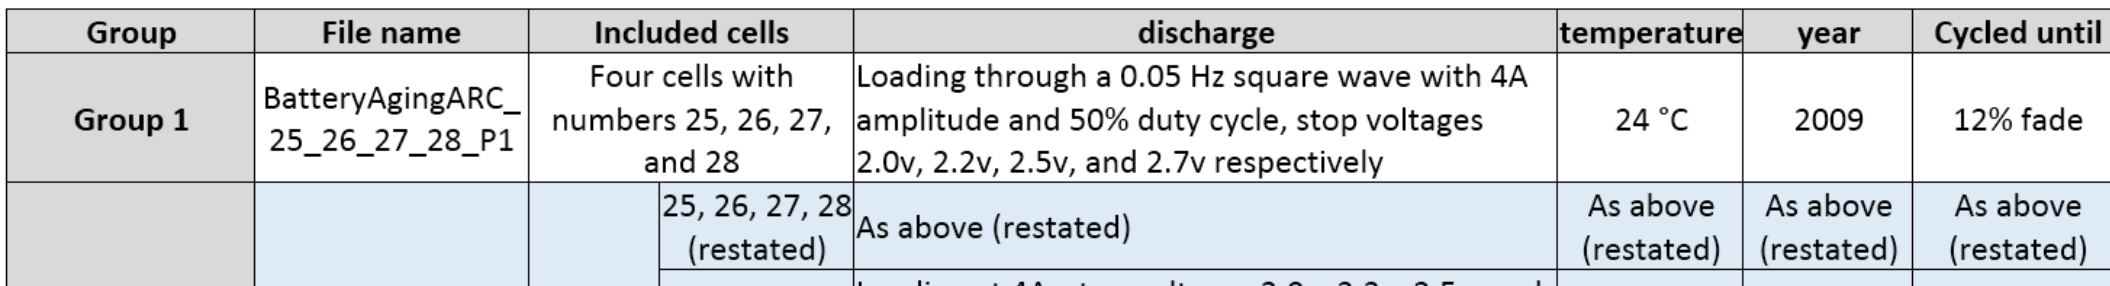

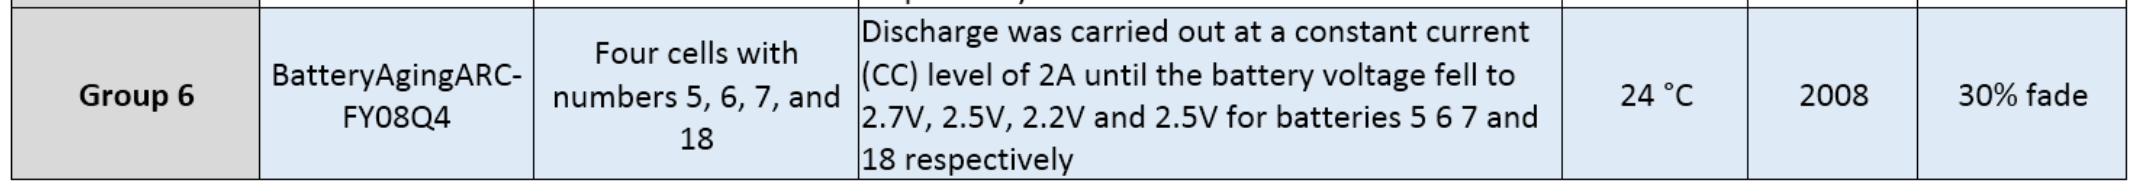

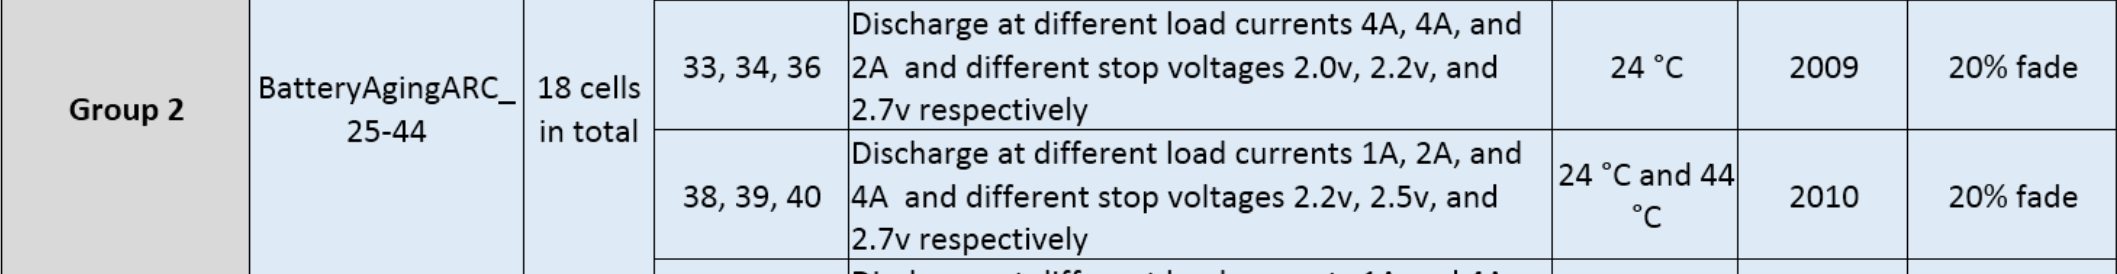

박종용 : discarge voltage 는 시나리오 만다 다르며 NASA 에서는 CC 로 전류소모 2.7볼트에서 cutfoff 

따라서 ageing 에 따라 capacity 가 떨어지고 2.7볼트로 떨어지는 시간이 빨라진다.

#### B007이 오래가는 이유 : 배터리특성. cutoff voltage 가 중요한 것이 아니라 그 시간이 중요하다. 이것을 결국 용량이다.

#### 그런데 이것은 더 시간이 길다. 그러므로 B0005 보다 오래 가는 이상한 결과를 보여준다.

clear % 이전 그래프는 지우지 않는다.
close all %  이전 그래프는 지운다.

% dischage cycle , select capacity
% constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively.
% DOD 가 높을수록 ( #7 ) Capacity 가 근방 줄어든다.

% 배터리 5,6,7은 사용자 패턴이 CC로 더 오래 사용하는가로 설명될 수 있다.


% https://stackoverflow.com/questions/7602816/notepad-incrementally-replace

%%%%%%%%%%%%%%%%%%%
% dischage cycle , select capacity
% constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively.
% DOD 가 높을수록 ( #7 ) Capacity 가 근방 줄어든다.

% A set of four Li-ion batteries (# 5, 6, 7 and 18) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode 
% at 1.5A 
% until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode 
% until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V 
% for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep 
% from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).

% 배터리 5,6,7은 사용자 패턴이 CC로 더 오래 사용하는가로 설명될 수 있다.



load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat

load B0025.mat
load B0026.mat
load B0027.mat
load B0028.mat

load B0029.mat
load B0030.mat
load B0031.mat
load B0032.mat

load B0033.mat
load B0034.mat
load B0036.mat

load B0038.mat
load B0039.mat
load B0040.mat

load B0041.mat
load B0042.mat
load B0043.mat
load B0044.mat

load B0045.mat
load B0046.mat
load B0047.mat
load B0048.mat

load B0049.mat
load B0050.mat
load B0051.mat
load B0052.mat

load B0053.mat
load B0054.mat
load B0055.mat
load B0056.mat

%{
% 읽기 실패
load B0125.mat
load B0126.mat
load B0127.mat
load B0128.mat
%}

%% 

cap05  = extract_discharge( B0005  );
cap06  = extract_discharge( B0006  );
cap07  = extract_discharge( B0007  );
cap18  = extract_discharge( B0018  );

cap25  = extract_discharge( B0025  );
cap26  = extract_discharge( B0026  );
cap27  = extract_discharge( B0027  );
cap28  = extract_discharge( B0028  );

cap29  = extract_discharge( B0029  );
cap30  = extract_discharge( B0030  );
cap31  = extract_discharge( B0031  );
cap32  = extract_discharge( B0032  );

cap33  = extract_discharge( B0033  );
cap34  = extract_discharge( B0034  );
cap36  = extract_discharge( B0036  );

cap38  = extract_discharge( B0038  );
cap39  = extract_discharge( B0039  );
cap40  = extract_discharge( B0040  );

cap41  = extract_discharge( B0041  );
cap42  = extract_discharge( B0042  );
cap43  = extract_discharge( B0043  );
cap44  = extract_discharge( B0044  );

cap45  = extract_discharge( B0045  );
cap46  = extract_discharge( B0046  );
cap47  = extract_discharge( B0047  );
cap48  = extract_discharge( B0048  );

%{
% 실험 소프트웨어가 깨져서 정상 데이타가 들어있지 않다.
cap49  = extract_discharge( B0049  );
cap50  = extract_discharge( B0050  );
cap51  = extract_discharge( B0051  );
cap52  = extract_discharge( B0052  );
%}
cap53  = extract_discharge( B0053  );
cap54  = extract_discharge( B0054  );
cap55  = extract_discharge( B0055  );
cap56  = extract_discharge( B0056  );

%{
% 읽기 실패
cap125 = extract_discharge( B0125 );
cap126 = extract_discharge( B0126 );
cap127 = extract_discharge( B0127 );
cap128 = extract_discharge( B0128 );
%}


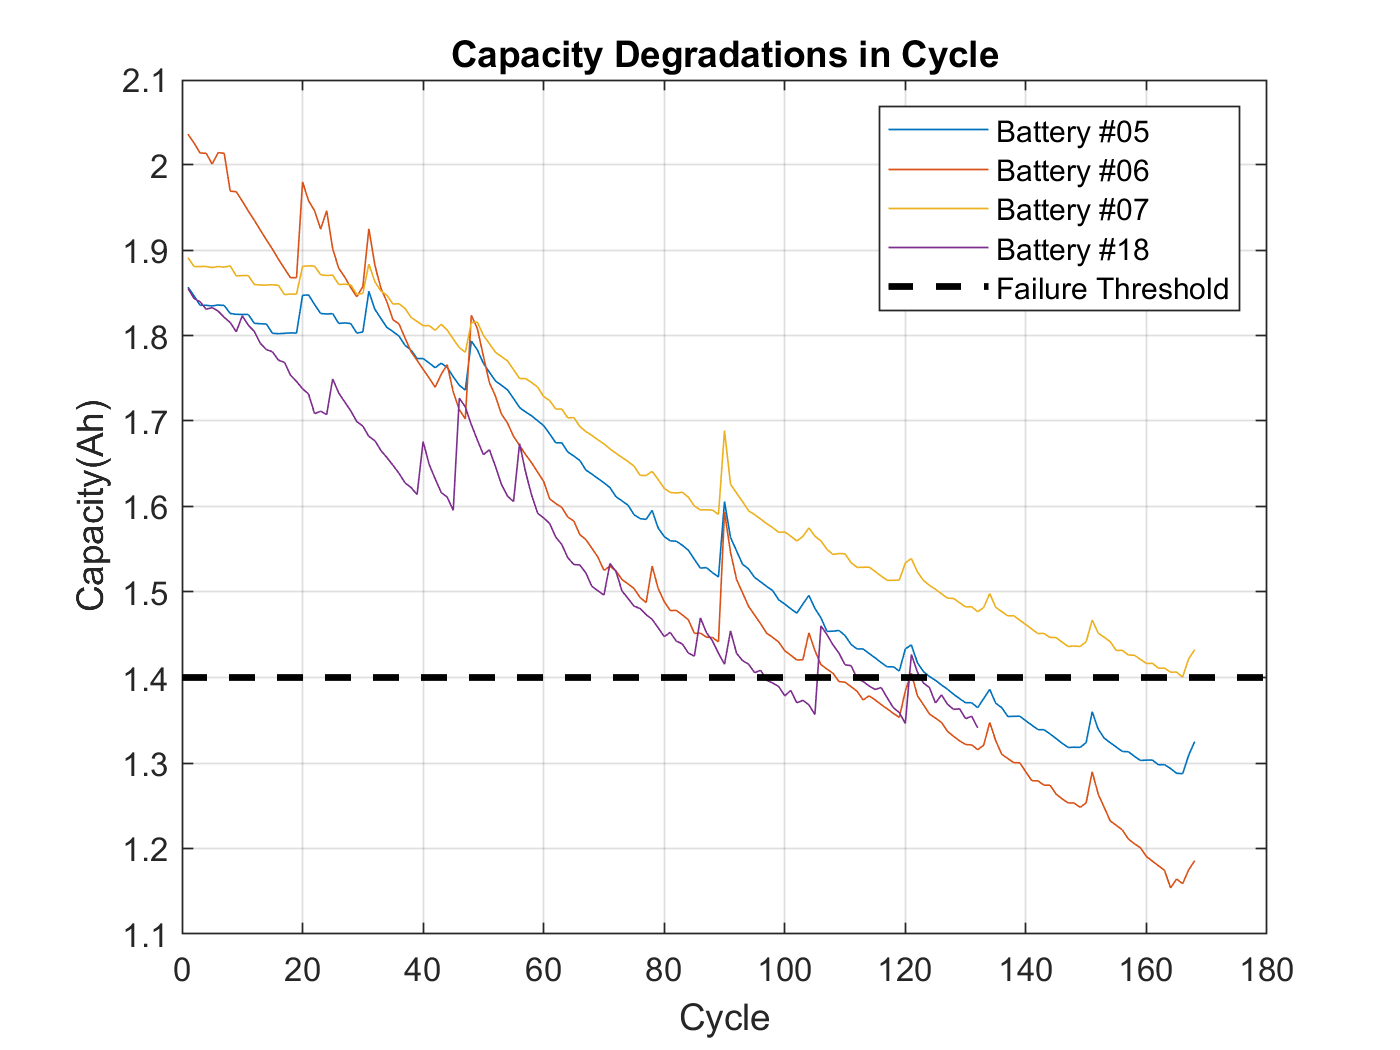


figure
plot(cap05), hold on, plot(cap06), plot(cap07), plot(cap18)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05', 'Battery #06', 'Battery #07', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

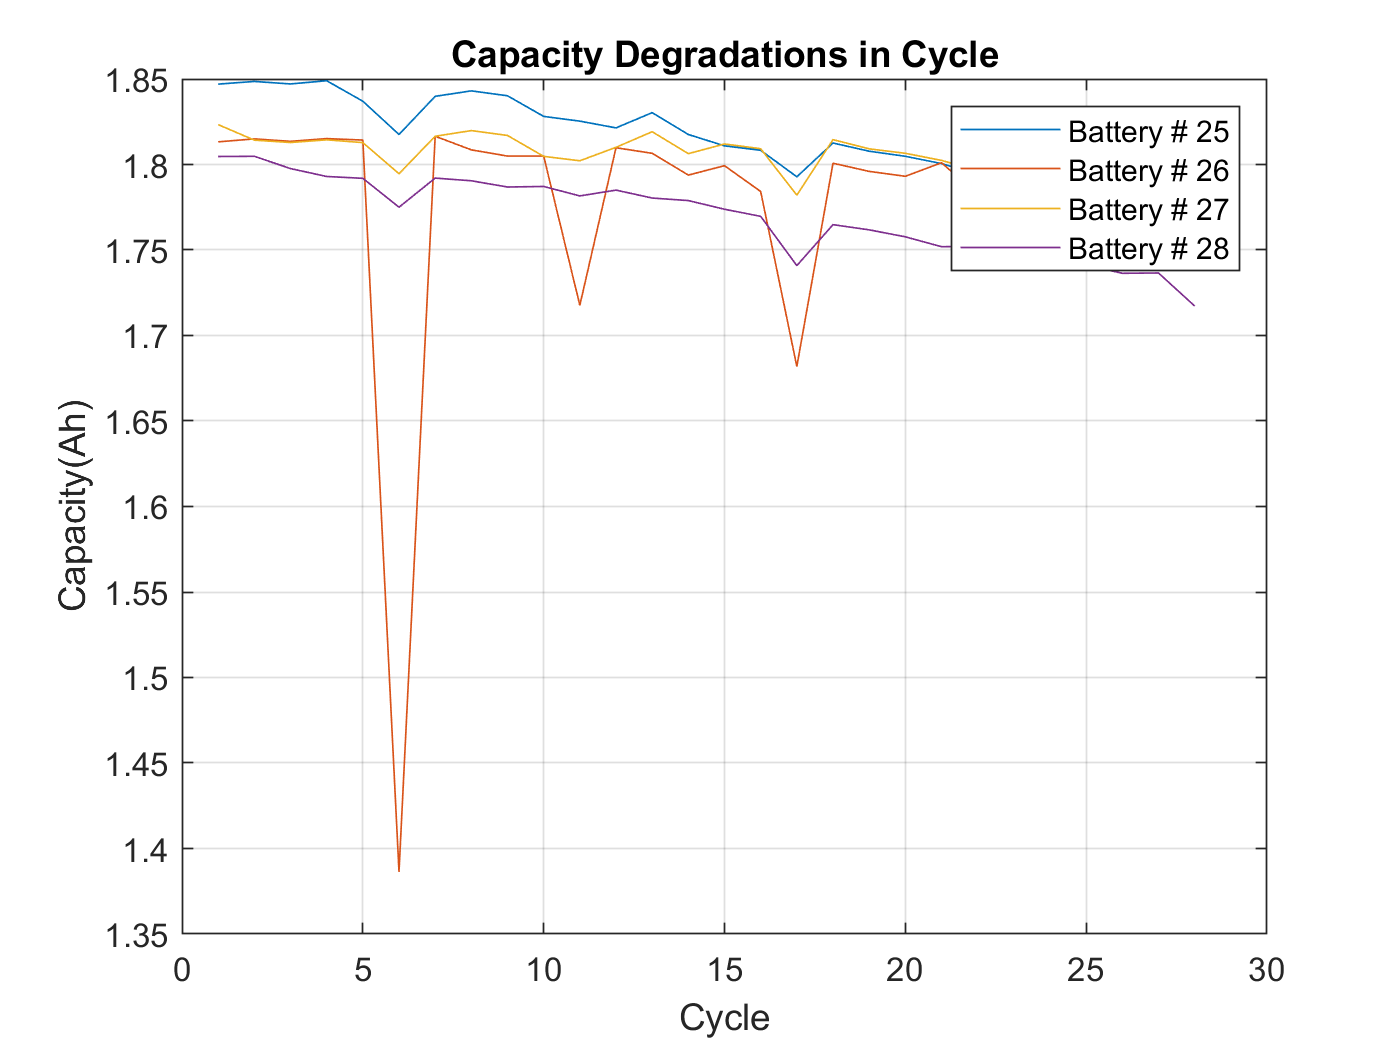

figure
plot(cap25), hold on, plot(cap26), plot(cap27), plot(cap28)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 25', 'Battery # 26', 'Battery # 27', 'Battery # 28')
title('Capacity Degradations in Cycle')

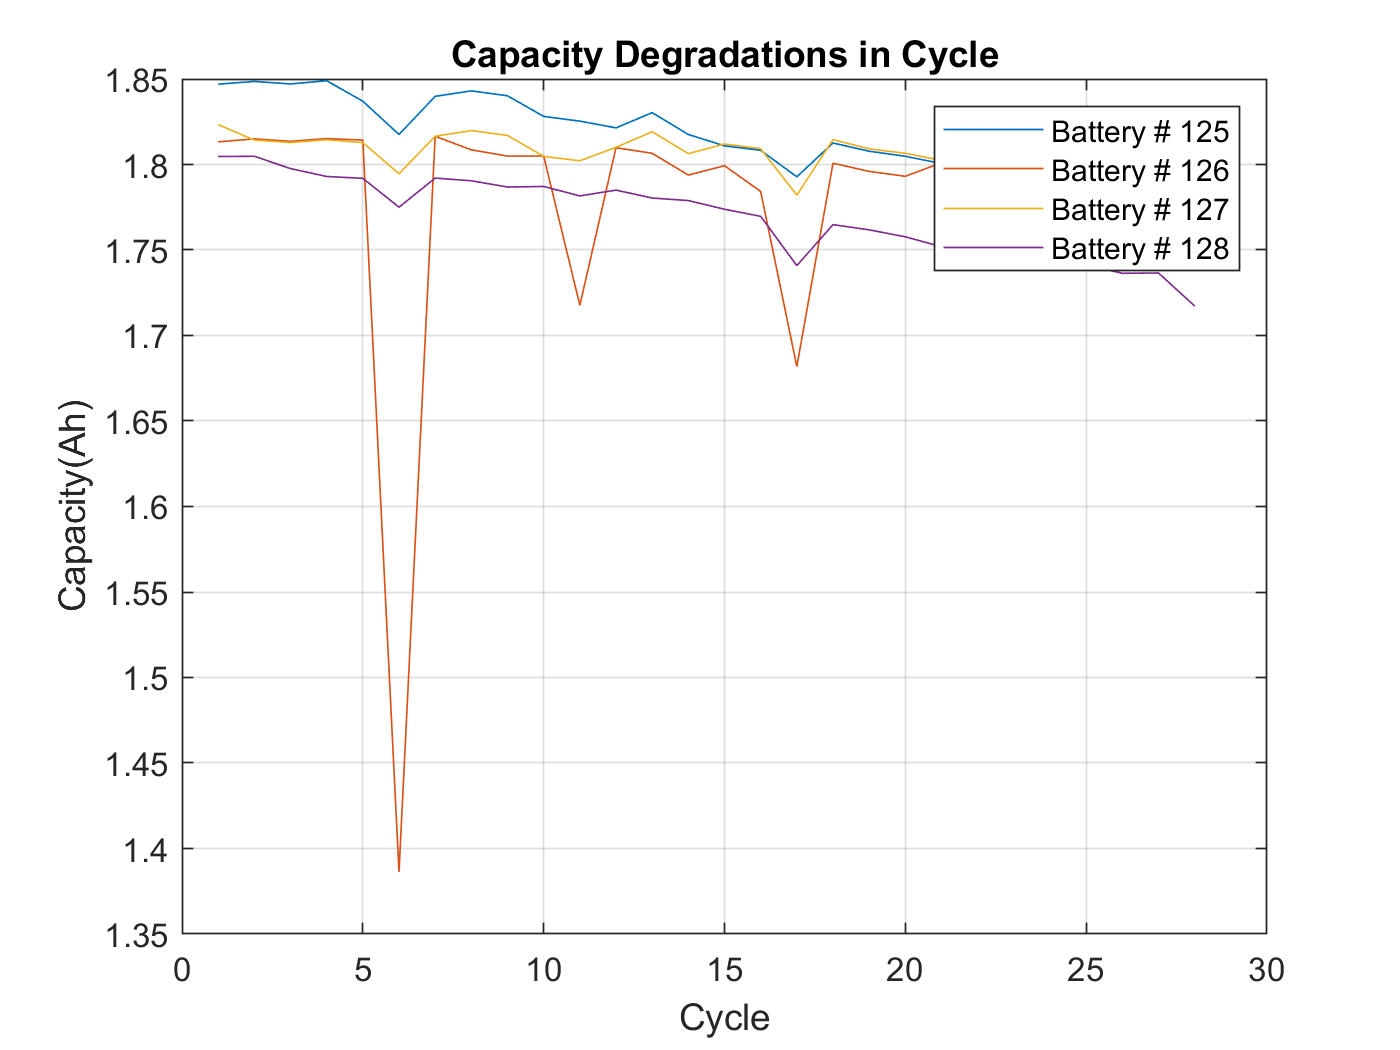

% 그래프가 동일하므로 제대로 된 mat 파일을 다시 가져오자.

% B0125.mat 파일을 열어보면 이름이 B025로 되어있다.
% google search : matlab rename mat name

% 이경우 B0125.mat 의 name이 B0025로 설정되어 있으며 로드한 경우 B0025 으로 되어있다.
% 기존의 B0025를 지우고 B0125.mat 을 로딩하면 workspace 에 B0025 으로 되어있는데 
% 이를 B0125 로 바꾼 후 B0125.mat로 저장하면 된다.
load B0125.mat
load B0126.mat
load B0127.mat
load B0128.mat

cap125 = extract_discharge( B0125 );
cap126 = extract_discharge( B0126 );
cap127 = extract_discharge( B0127 );
cap128 = extract_discharge( B0128 );

figure
plot(cap125), hold on, plot(cap126), plot(cap127), plot(cap128)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 125', 'Battery # 126', 'Battery # 127', 'Battery # 128')
title('Capacity Degradations in Cycle')

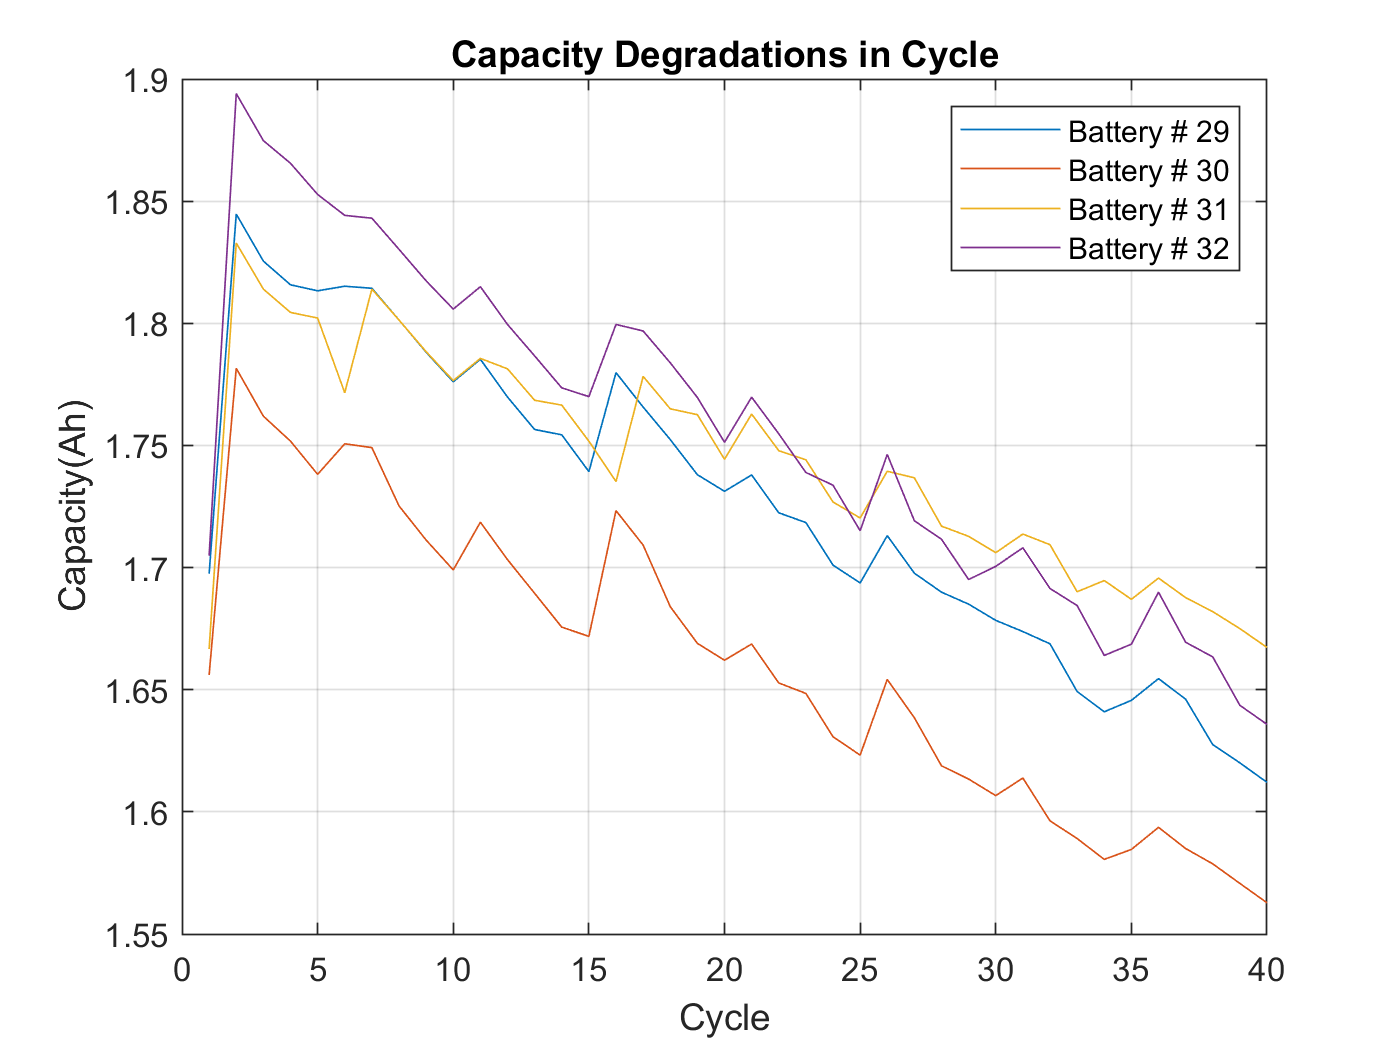

figure
plot(cap29), hold on, plot(cap30), plot(cap31), plot(cap32)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 29', 'Battery # 30', 'Battery # 31', 'Battery # 32')
title('Capacity Degradations in Cycle')

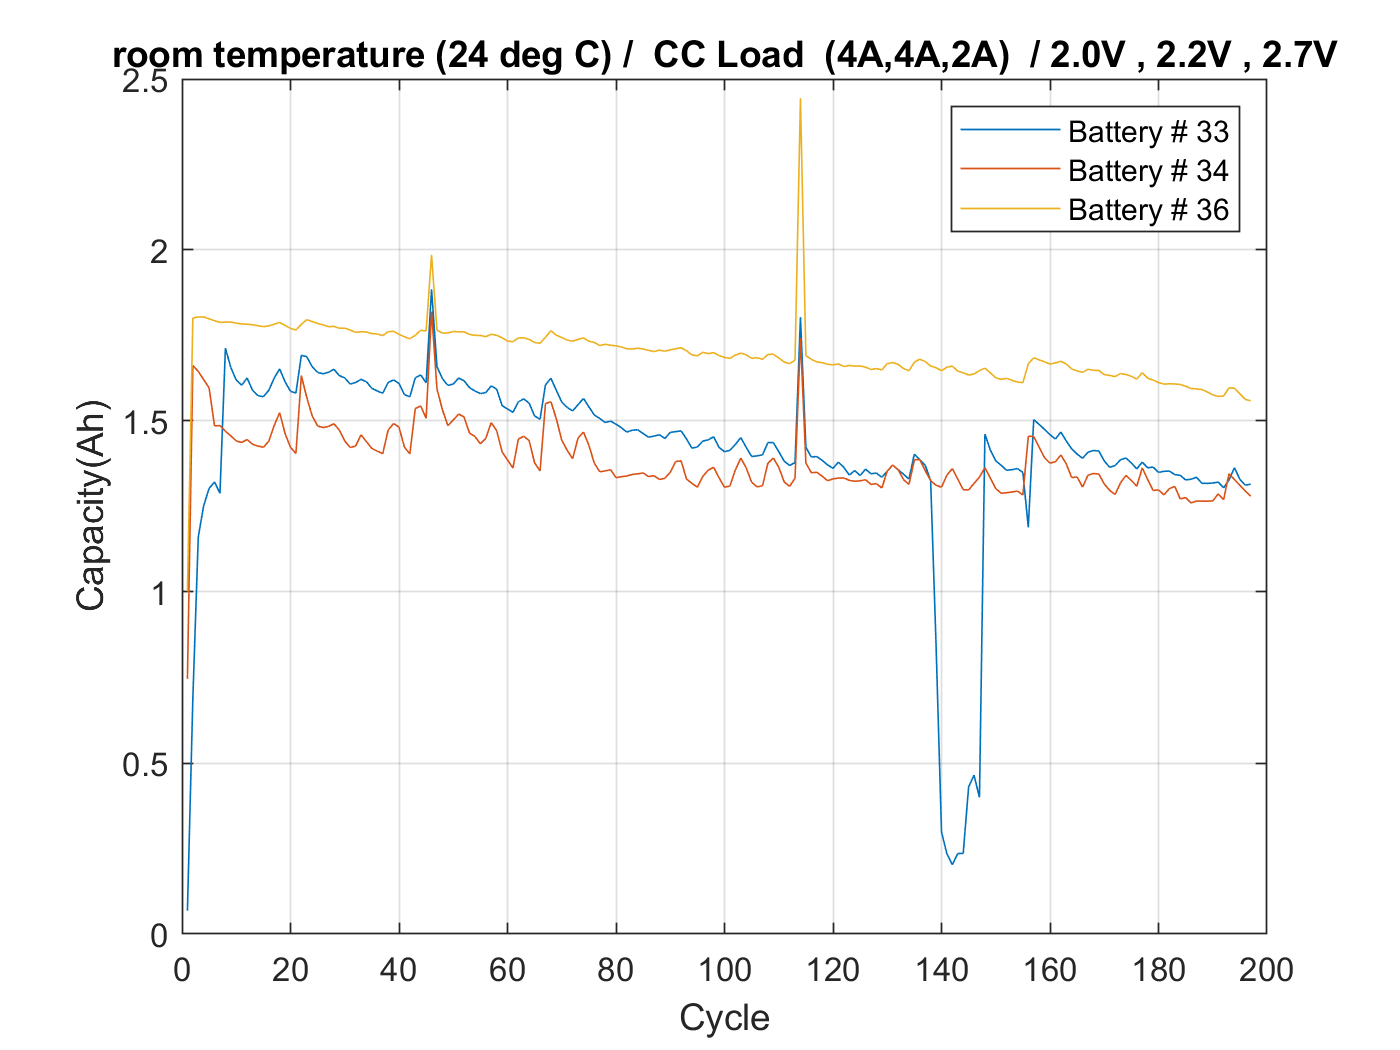

figure
plot(cap33), hold on, plot(cap34), plot(cap36)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 33', 'Battery # 34', 'Battery # 36')
%title('Capacity Degradations in Cycle')
title('room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V')

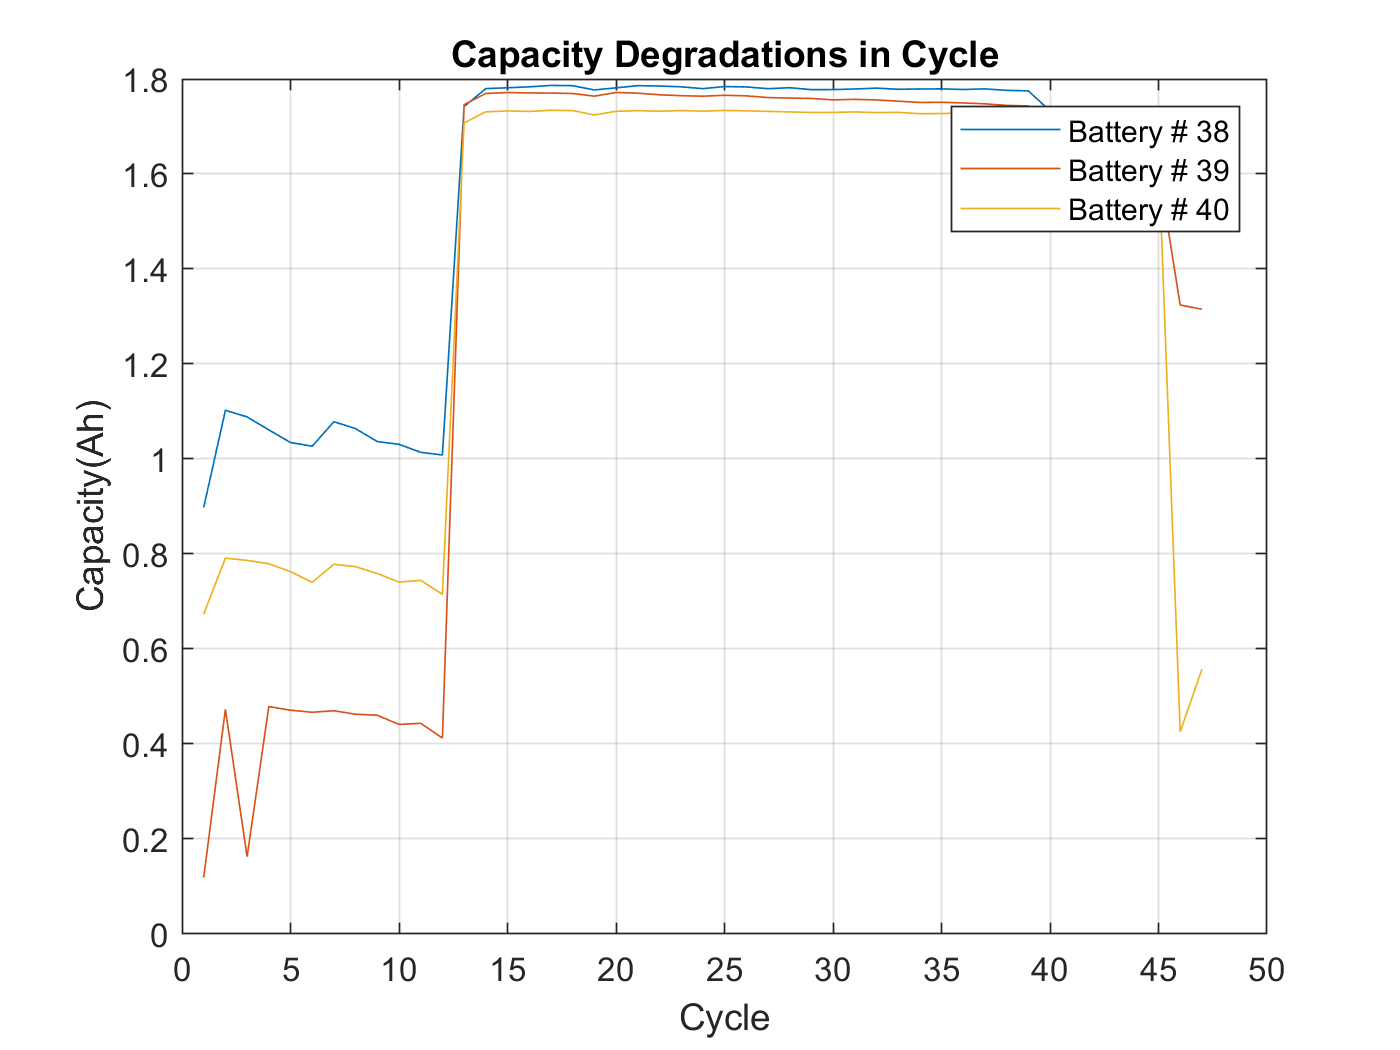

figure
plot(cap38), hold on, plot(cap39), plot(cap40)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 38', 'Battery # 39', 'Battery # 40')
title('Capacity Degradations in Cycle')

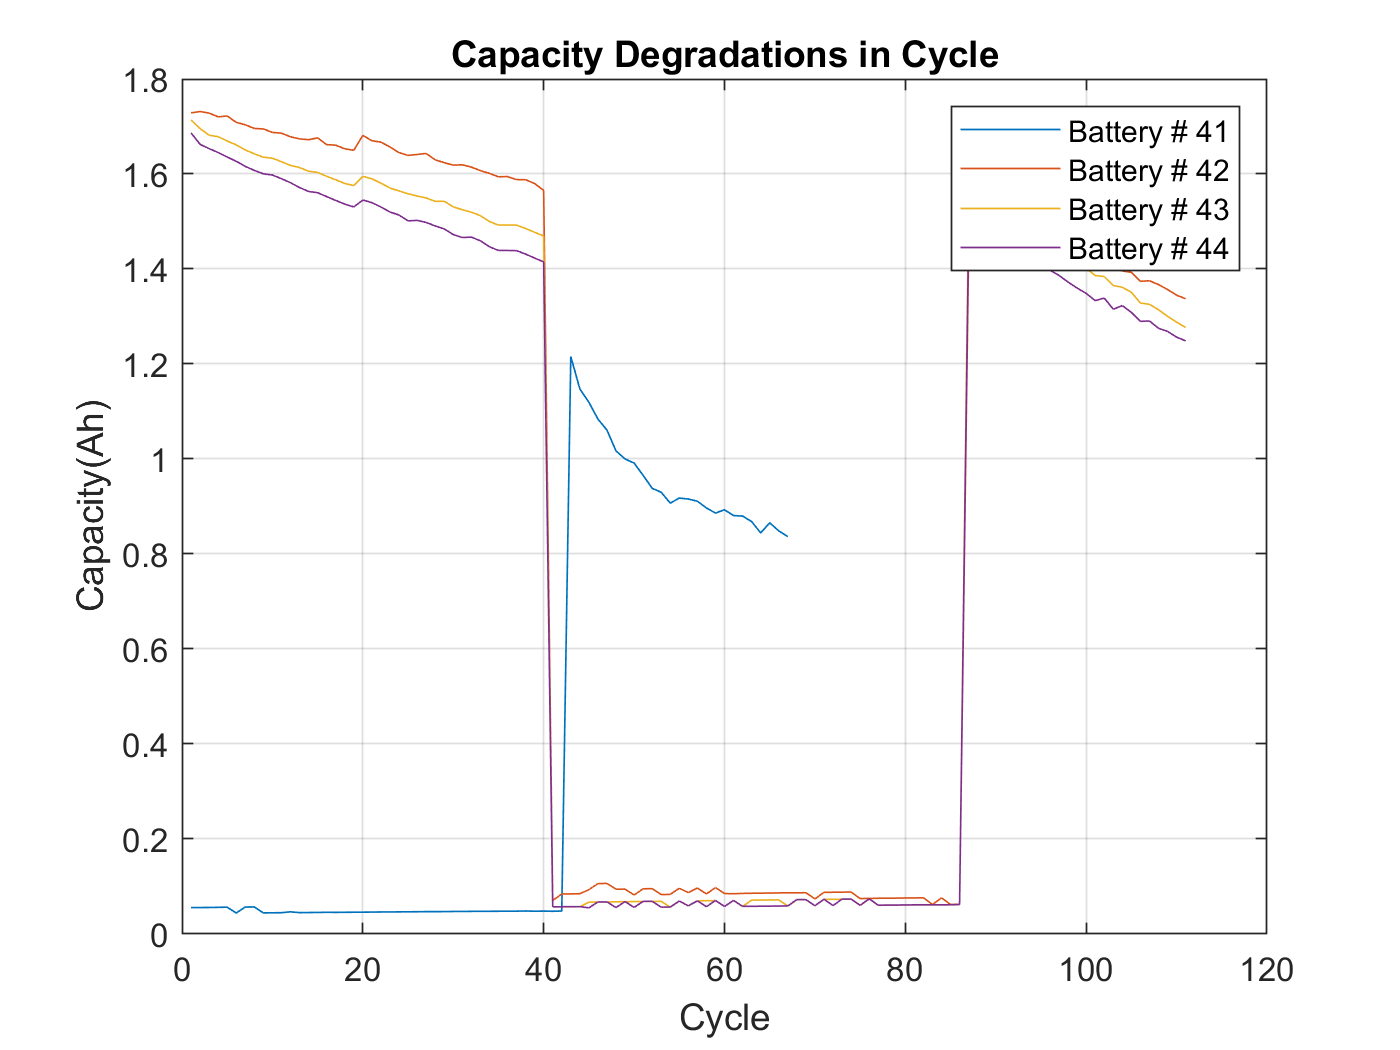

figure
plot(cap41), hold on, plot(cap42), plot(cap43), plot(cap44)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 41', 'Battery # 42', 'Battery # 43', 'Battery # 44')
title('Capacity Degradations in Cycle')

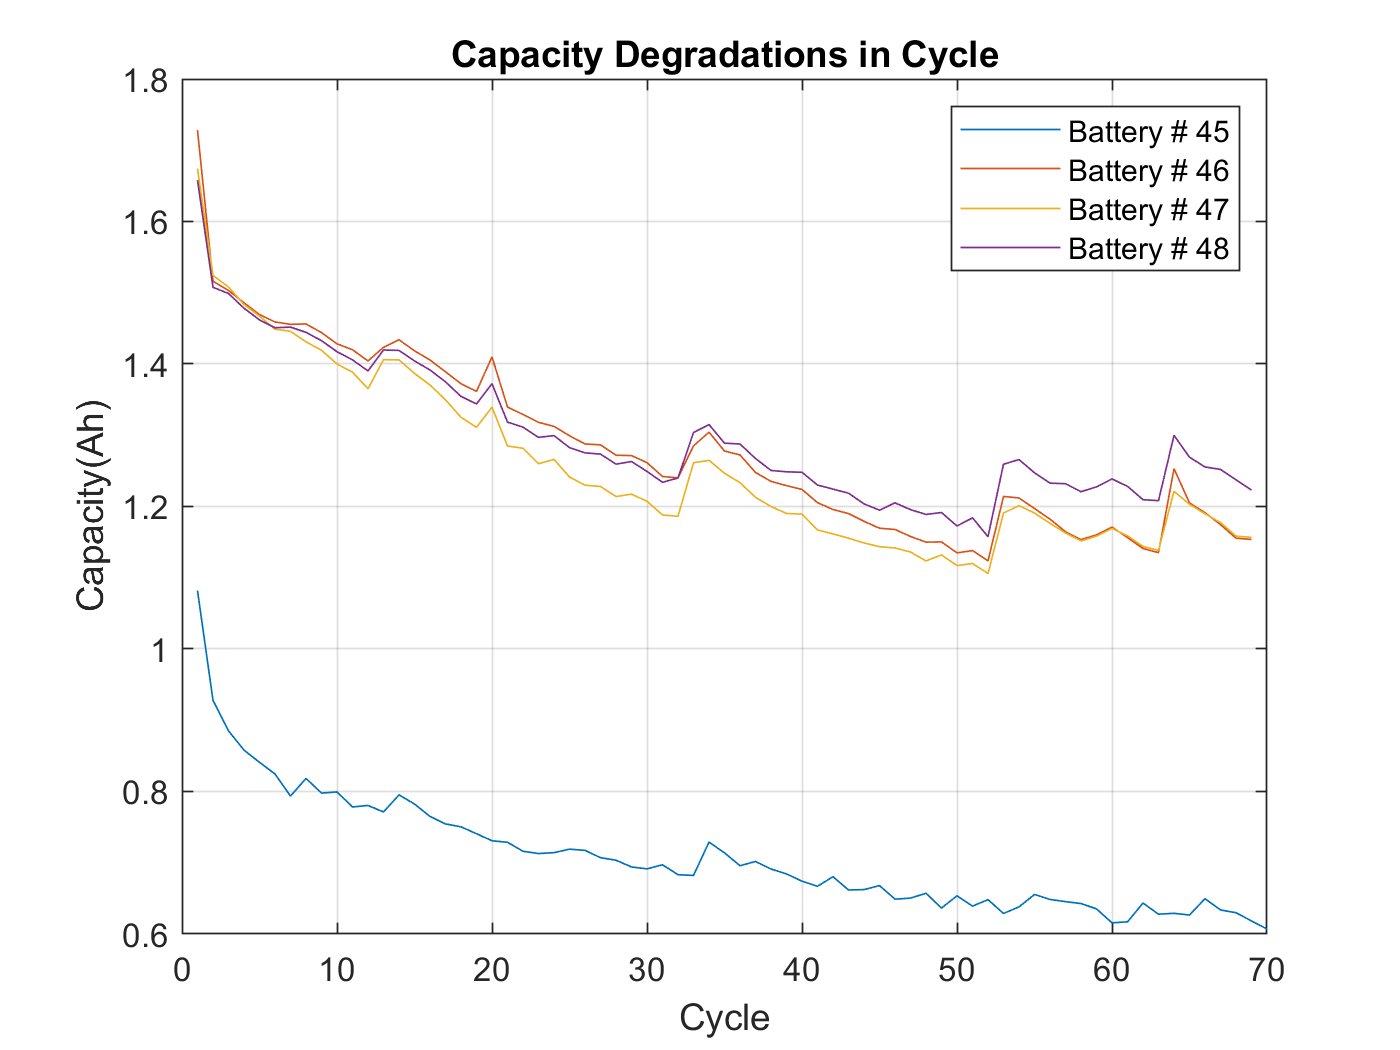

figure
plot(cap45), hold on, plot(cap46), plot(cap47), plot(cap48)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 45', 'Battery # 46', 'Battery # 47', 'Battery # 48')
title('Capacity Degradations in Cycle')

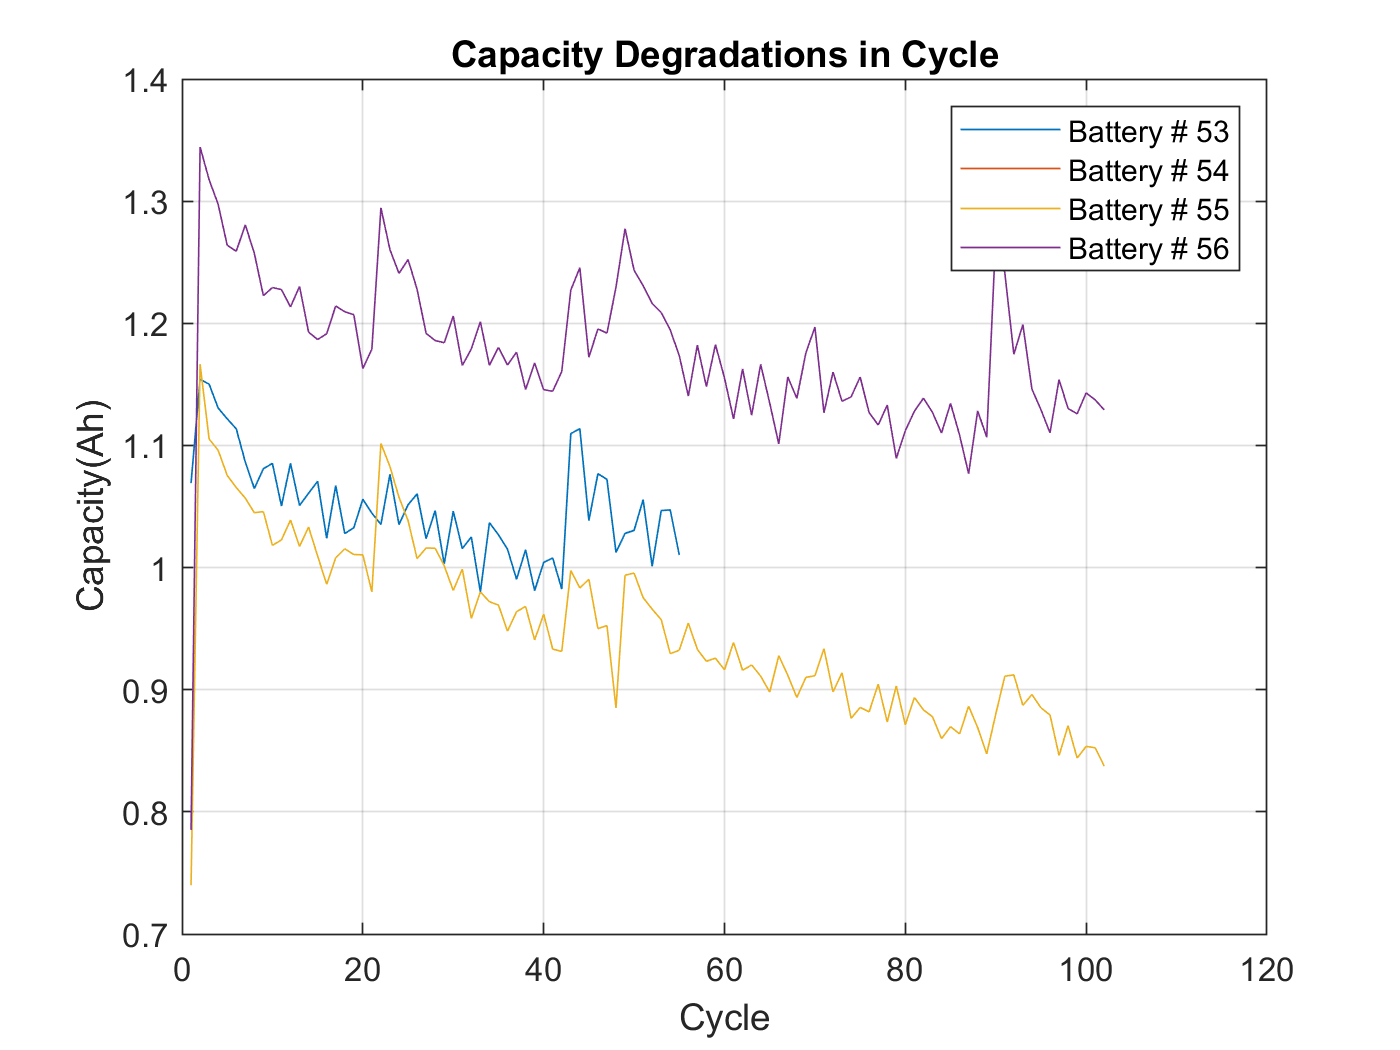

%{
figure
plot(cap49), hold on, plot(cap50), plot(cap51), plot(cap51)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 49', 'Battery # 50', 'Battery # 51', 'Battery # 52')
title('Capacity Degradations in Cycle')

%}

figure

plot(cap53), hold on, plot(cap54), plot(cap54), plot(cap56)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 53', 'Battery # 54', 'Battery # 55', 'Battery # 56')
title('Capacity Degradations in Cycle')

실제 논문에서 적용 가능한 데이타들 ( 기본 + 34,36)

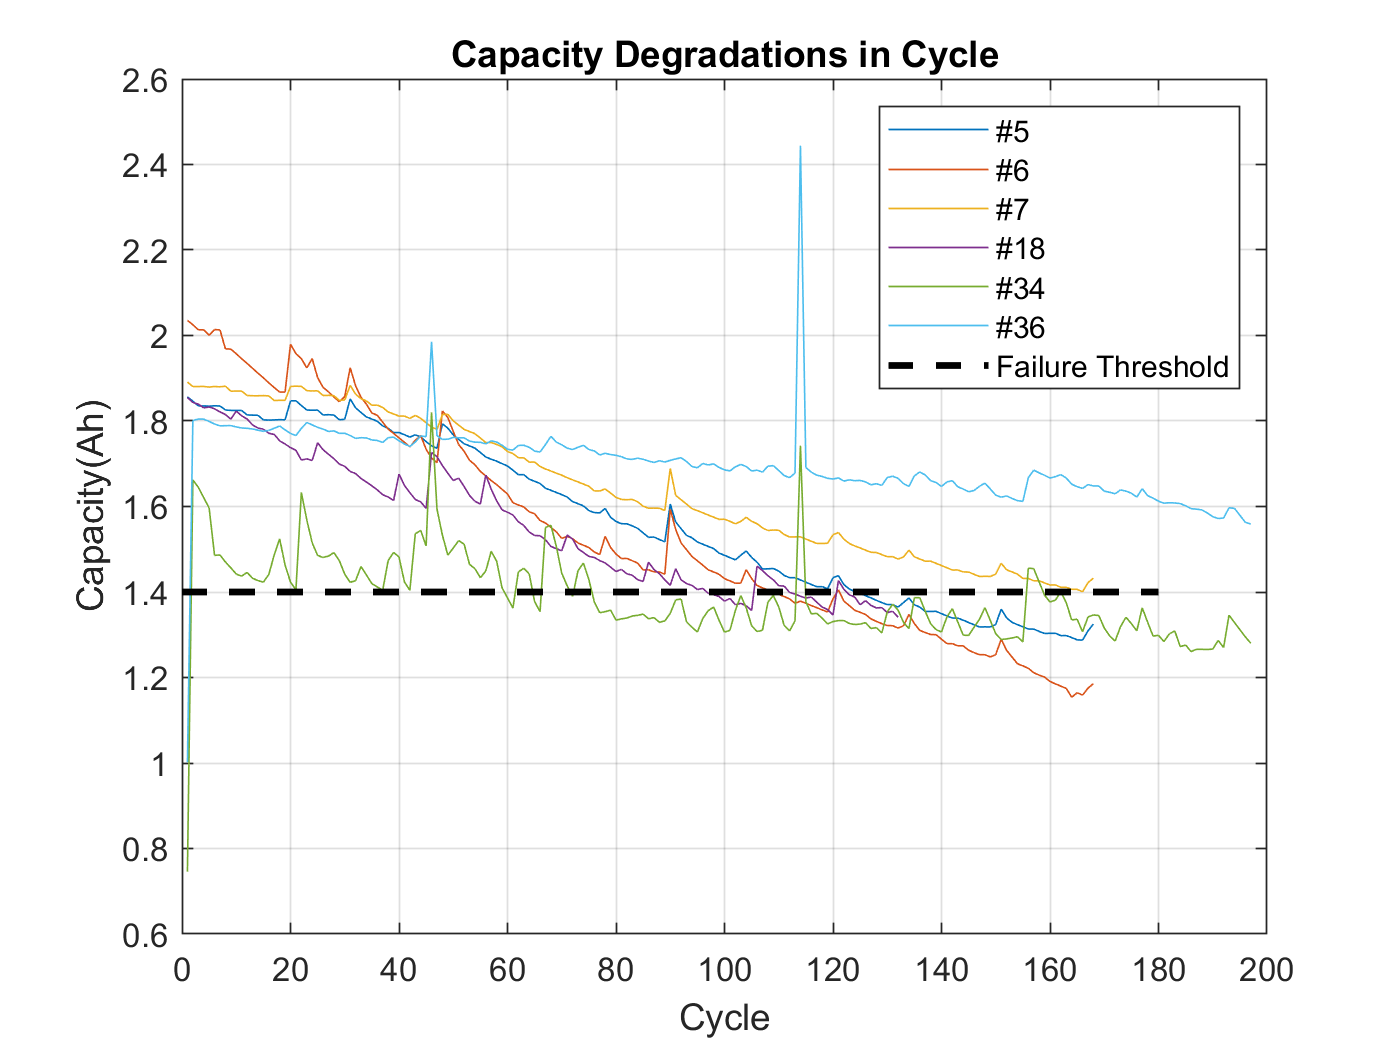

figure
plot(cap05), hold on, plot(cap06), plot(cap07), plot(cap18), plot(cap34), plot(cap36)

plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#34','#36','Failure Threshold')
title('Capacity Degradations in Cycle')

# Data Processing - Remove Regeneration - ARIMA 분석 - #5 #6을 사용하자


% A set of four Li-ion batteries (# 5, 6, 7 and 18) 
% were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).


#### room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V = 33번 측정이상이 있음.

Data Description:

A set of three Li-ion batteries (# 33, 34 and 36) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature (24 deg C). Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A** until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively. For **battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

Files:

B0033.mat	Data for Battery #33

B0034.mat	Data for Battery #34

B0036.mat	Data for Battery #36

%  (24 deg C). 
% Charging was carried out in a constant current (CC) mode at 1.5A 
% until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode 
% until the charge current dropped to 20mA. 
% Discharge was carried out at 4A until the battery voltage fell to 2.0V and 2.2V 
% for batteries 33 and 34 respectively. 
% For battery 36 discharge was done at 2A until voltage fell to 2.7V. 

%result = [cap',cycleTimeHour',restTimeHour',restCycle',cCCEndTimeSec',cTempMaxDt',cCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dCcEndTimeSec' ];
%result = [cap',cycleTimeHourHour',restTimeHourHour',restCycle',cTempMax',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',cCcEndTimeSec',dCcEndTimeSec' ];
%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cCcEndTimeSec',dTempMax',dCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe' ];

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;

pattern_temp05_const = 24;
pattern_temp06_const = 24;
pattern_temp07_const = 24;
pattern_temp18_const = 24;
pattern_temp29_const = 43;
pattern_temp30_const = 43;
pattern_temp31_const = 43;
pattern_temp32_const = 43;
pattern_temp33_const = 24;
pattern_temp34_const = 24;
pattern_temp36_const = 24;

pattern_CC_amps05_const = 2;
pattern_CC_amps06_const = 2;
pattern_CC_amps07_const = 2;
pattern_CC_amps18_const = 2;
pattern_CC_amps29_const = 4;
pattern_CC_amps30_const = 4;
pattern_CC_amps31_const = 4;
pattern_CC_amps32_const = 4;
pattern_CC_amps33_const = 4;
pattern_CC_amps34_const = 4;
pattern_CC_amps36_const = 2;

pattern_dVolt05_const = 4.2 - 2.7 ; 
pattern_dVolt06_const = 4.2 - 2.5 ; 
pattern_dVolt07_const = 4.2 - 2.2 ; 
pattern_dVolt18_const = 4.2 - 2.5 ; 
pattern_dVolt29_const = 4.2 - 2.0 ;   
pattern_dVolt30_const = 4.2 - 2.2 ;   
pattern_dVolt31_const = 4.2 - 2.5 ;   
pattern_dVolt32_const = 4.2 - 2.7 ;   
pattern_dVolt33_const = 4.2 - 2.0 ; 
pattern_dVolt34_const = 4.2 - 2.2 ; 
pattern_dVolt36_const = 4.2 - 2.7 ; 



result_05 = extract_feature_all_v2(B0005,0,cap05);
result_06 = extract_feature_all_v2(B0006,0,cap06);
result_07 = extract_feature_all_v2(B0007,0,cap07);
result_18 = extract_feature_all_v2(B0018,0,cap18);
result_29 = extract_feature_all_v2(B0029,0,cap29);
result_30 = extract_feature_all_v2(B0030,0,cap30);
result_31 = extract_feature_all_v2(B0031,0,cap31);
result_32 = extract_feature_all_v2(B0032,0,cap32);
result_33 = extract_feature_all_v2(B0033,0,cap33);
result_34 = extract_feature_all_v2(B0034,0,cap34);
result_36 = extract_feature_all_v2(B0036,0,cap36);



pattern_dVolt_vector   = ones(length(result_05),1) *  pattern_dVolt05_const; result_05 = [result_05,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_06),1) *  pattern_dVolt06_const; result_06 = [result_06,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_07),1) *  pattern_dVolt07_const; result_07 = [result_07,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_18),1) *  pattern_dVolt18_const; result_18 = [result_18,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_29),1) *  pattern_dVolt29_const; result_29 = [result_29,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_30),1) *  pattern_dVolt30_const; result_30 = [result_30,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_31),1) *  pattern_dVolt31_const; result_31 = [result_31,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_32),1) *  pattern_dVolt32_const; result_32 = [result_32,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_33),1) *  pattern_dVolt33_const; result_33 = [result_33,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_34),1) *  pattern_dVolt34_const; result_34 = [result_34,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_36),1) *  pattern_dVolt36_const; result_36 = [result_36,pattern_dVolt_vector];

pattern_temp_vector   = ones(length(result_05),1) *  pattern_temp05_const; result_05 = [result_05,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_06),1) *  pattern_temp06_const; result_06 = [result_06,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_07),1) *  pattern_temp07_const; result_07 = [result_07,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_18),1) *  pattern_temp18_const; result_18 = [result_18,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_29),1) *  pattern_temp29_const; result_29 = [result_29,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_30),1) *  pattern_temp30_const; result_30 = [result_30,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_31),1) *  pattern_temp31_const; result_31 = [result_31,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_32),1) *  pattern_temp32_const; result_32 = [result_32,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_33),1) *  pattern_temp33_const; result_33 = [result_33,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_34),1) *  pattern_temp34_const; result_34 = [result_34,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_36),1) *  pattern_temp36_const; result_36 = [result_36,pattern_temp_vector];


pattern_CC_amps_vector   = ones(length(result_05),1) *  pattern_CC_amps05_const; result_05 = [result_05,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_06),1) *  pattern_CC_amps06_const; result_06 = [result_06,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_07),1) *  pattern_CC_amps07_const; result_07 = [result_07,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_18),1) *  pattern_CC_amps18_const; result_18 = [result_18,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_29),1) *  pattern_CC_amps29_const; result_29 = [result_29,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_30),1) *  pattern_CC_amps30_const; result_30 = [result_30,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_31),1) *  pattern_CC_amps31_const; result_31 = [result_31,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_32),1) *  pattern_CC_amps32_const; result_32 = [result_32,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_33),1) *  pattern_CC_amps33_const; result_33 = [result_33,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_34),1) *  pattern_CC_amps34_const; result_34 = [result_34,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_36),1) *  pattern_CC_amps36_const; result_36 = [result_36,pattern_CC_amps_vector];

%% remove rest cycle 
restCycleTF_raw_index = find (result_05(:,restCycleIdx) == 1 )'; result_05(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_06(:,restCycleIdx) == 1 )'; result_06(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_07(:,restCycleIdx) == 1 )'; result_07(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_18(:,restCycleIdx) == 1 )'; result_18(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_29(:,restCycleIdx) == 1 )'; result_29(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_30(:,restCycleIdx) == 1 )'; result_30(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_31(:,restCycleIdx) == 1 )'; result_31(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_32(:,restCycleIdx) == 1 )'; result_32(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_33(:,restCycleIdx) == 1 )'; result_33(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_34(:,restCycleIdx) == 1 )'; result_34(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_36(:,restCycleIdx) == 1 )'; result_36(restCycleTF_raw_index,:)=[];

               
i = 1;
capacity05 = result_05(:,i); 
capacity06 = result_06(:,i); 
capacity07 = result_07(:,i); 
capacity18 = result_18(:,i); 
capacity29 = result_29(:,i); 
capacity30 = result_30(:,i); 
capacity31 = result_31(:,i); 
capacity32 = result_32(:,i); 
capacity33 = result_33(:,i); 
capacity34 = result_34(:,i); 
capacity36 = result_36(:,i); 

% base is 2V 
capacityNorm05 = result_05(:,i) + 2 - result_05(1,i); 
capacityNorm06 = result_06(:,i) + 2 - result_06(1,i); 
capacityNorm07 = result_07(:,i) + 2 - result_07(1,i); 
capacityNorm18 = result_18(:,i) + 2 - result_18(1,i); 
capacityNorm29 = result_29(:,i) + 2 - result_29(1,i); 
capacityNorm30 = result_30(:,i) + 2 - result_30(1,i); 
capacityNorm31 = result_31(:,i) + 2 - result_31(1,i); 
capacityNorm32 = result_32(:,i) + 2 - result_32(1,i); 
capacityNorm33 = result_33(:,i) + 2 - result_33(1,i); 
capacityNorm34 = result_34(:,i) + 2 - result_34(1,i); 
capacityNorm36 = result_36(:,i) + 2 - result_36(1,i); 

i =  i + 1;
cycleTimeHour05 = result_05(:,i); 
cycleTimeHour06 = result_06(:,i); 
cycleTimeHour07 = result_07(:,i); 
cycleTimeHour18 = result_18(:,i); 
cycleTimeHour29 = result_29(:,i); 
cycleTimeHour30 = result_30(:,i); 
cycleTimeHour31 = result_31(:,i); 
cycleTimeHour32 = result_32(:,i); 
cycleTimeHour33 = result_33(:,i); 
cycleTimeHour34 = result_34(:,i); 
cycleTimeHour36 = result_36(:,i); 

i =  i + 1;
restTimeHour05 = result_05(:,i); 
restTimeHour06 = result_06(:,i); 
restTimeHour07 = result_07(:,i); 
restTimeHour18 = result_18(:,i); 
restTimeHour29 = result_29(:,i); 
restTimeHour30 = result_30(:,i); 
restTimeHour31 = result_31(:,i); 
restTimeHour32 = result_32(:,i); 
restTimeHour33 = result_33(:,i); 
restTimeHour34 = result_34(:,i); 
restTimeHour36 = result_36(:,i); 

i =  i + 1;
restCycle05 = result_05(:,i); 
restCycle06 = result_06(:,i); 
restCycle07 = result_07(:,i); 
restCycle18 = result_18(:,i); 
restCycle29 = result_29(:,i); 
restCycle30 = result_30(:,i); 
restCycle31 = result_31(:,i); 
restCycle32 = result_32(:,i); 
restCycle33 = result_33(:,i); 
restCycle34 = result_34(:,i); 
restCycle36 = result_36(:,i); 

i =  i + 1;
cTempMax05 = result_05(:,i); 
cTempMax06 = result_06(:,i); 
cTempMax07 = result_07(:,i); 
cTempMax18 = result_18(:,i); 
cTempMax29 = result_29(:,i); 
cTempMax30 = result_30(:,i); 
cTempMax31 = result_31(:,i); 
cTempMax32 = result_32(:,i); 
cTempMax33 = result_33(:,i); 
cTempMax34 = result_34(:,i); 
cTempMax36 = result_36(:,i); 

i =  i + 1;
cCcEndTimeSec05 = result_05(:,i); 
cCcEndTimeSec06 = result_06(:,i); 
cCcEndTimeSec07 = result_07(:,i); 
cCcEndTimeSec18 = result_18(:,i); 
cCcEndTimeSec29 = result_29(:,i); 
cCcEndTimeSec30 = result_30(:,i); 
cCcEndTimeSec31 = result_31(:,i); 
cCcEndTimeSec32 = result_32(:,i); 
cCcEndTimeSec33 = result_33(:,i); 
cCcEndTimeSec34 = result_34(:,i); 
cCcEndTimeSec36 = result_36(:,i); 

i =  i + 1;
dTempMax05 = result_05(:,i); 
dTempMax06 = result_06(:,i); 
dTempMax07 = result_07(:,i); 
dTempMax18 = result_18(:,i); 
dTempMax29 = result_29(:,i); 
dTempMax30 = result_30(:,i); 
dTempMax31 = result_31(:,i); 
dTempMax32 = result_32(:,i); 
dTempMax33 = result_33(:,i); 
dTempMax34 = result_34(:,i); 
dTempMax36 = result_36(:,i); 

i =  i + 1;
dCcEndTimeSec05 = result_05(:,i); 
dCcEndTimeSec06 = result_06(:,i); 
dCcEndTimeSec07 = result_07(:,i); 
dCcEndTimeSec18 = result_18(:,i); 
dCcEndTimeSec29 = result_29(:,i); 
dCcEndTimeSec30 = result_30(:,i); 
dCcEndTimeSec31 = result_31(:,i); 
dCcEndTimeSec32 = result_32(:,i); 
dCcEndTimeSec33 = result_33(:,i); 
dCcEndTimeSec34 = result_34(:,i); 
dCcEndTimeSec36 = result_36(:,i); 

i =  i + 1;
ohm05 = result_05(:,i); 
ohm06 = result_06(:,i); 
ohm07 = result_07(:,i); 
ohm18 = result_18(:,i); 
ohm29 = result_29(:,i); 
ohm30 = result_30(:,i); 
ohm31 = result_31(:,i); 
ohm32 = result_32(:,i); 
ohm33 = result_33(:,i); 
ohm34 = result_34(:,i); 
ohm36 = result_36(:,i); 

i =  i + 1;
re_c05 = result_05(:,i); 
re_c06 = result_06(:,i); 
re_c07 = result_07(:,i); 
re_c18 = result_18(:,i); 
re_c29 = result_29(:,i); 
re_c30 = result_30(:,i); 
re_c31 = result_31(:,i); 
re_c32 = result_32(:,i); 
re_c33 = result_33(:,i); 
re_c34 = result_34(:,i); 
re_c36 = result_36(:,i); 


i =  i + 1;
re_d05 = result_05(:,i); 
re_d06 = result_06(:,i); 
re_d07 = result_07(:,i); 
re_d18 = result_18(:,i); 
re_d29 = result_29(:,i); 
re_d30 = result_30(:,i); 
re_d31 = result_31(:,i); 
re_d32 = result_32(:,i); 
re_d33 = result_33(:,i); 
re_d34 = result_34(:,i); 
re_d36 = result_36(:,i); 

i =  i + 1;
cycleNoChageRe05 = result_05(:,i); 
cycleNoChageRe06 = result_06(:,i); 
cycleNoChageRe07 = result_07(:,i); 
cycleNoChageRe18 = result_18(:,i); 
cycleNoChageRe29 = result_29(:,i); 
cycleNoChageRe30 = result_30(:,i); 
cycleNoChageRe31 = result_31(:,i); 
cycleNoChageRe32 = result_32(:,i); 
cycleNoChageRe33 = result_33(:,i); 
cycleNoChageRe34 = result_34(:,i); 
cycleNoChageRe36 = result_36(:,i); 

i =  i + 1;
cycleNoDischageRe05 = result_05(:,i); 
cycleNoDischageRe06 = result_06(:,i); 
cycleNoDischageRe07 = result_07(:,i); 
cycleNoDischageRe18 = result_18(:,i); 
cycleNoDischageRe29 = result_29(:,i); 
cycleNoDischageRe30 = result_30(:,i); 
cycleNoDischageRe31 = result_31(:,i); 
cycleNoDischageRe32 = result_32(:,i); 
cycleNoDischageRe33 = result_33(:,i); 
cycleNoDischageRe34 = result_34(:,i); 
cycleNoDischageRe36 = result_36(:,i); 



i =  i + 1;
pattern_dVolt05 = result_05(:,i); 
pattern_dVolt06 = result_06(:,i); 
pattern_dVolt07 = result_07(:,i); 
pattern_dVolt18 = result_18(:,i); 
pattern_dVolt29 = result_29(:,i); 
pattern_dVolt30 = result_30(:,i); 
pattern_dVolt31 = result_31(:,i); 
pattern_dVolt32 = result_32(:,i); 
pattern_dVolt33 = result_33(:,i); 
pattern_dVolt34 = result_34(:,i); 
pattern_dVolt36 = result_36(:,i); 

i =  i + 1;
pattern_temp05 = result_05(:,i); 
pattern_temp06 = result_06(:,i); 
pattern_temp07 = result_07(:,i); 
pattern_temp18 = result_18(:,i); 
pattern_temp29 = result_29(:,i); 
pattern_temp30 = result_30(:,i); 
pattern_temp31 = result_31(:,i); 
pattern_temp32 = result_32(:,i); 
pattern_temp33 = result_33(:,i); 
pattern_temp34 = result_34(:,i); 
pattern_temp36 = result_36(:,i); 

i =  i + 1;
pattern_CC_amps05 = result_05(:,i); 
pattern_CC_amps06 = result_06(:,i); 
pattern_CC_amps07 = result_07(:,i); 
pattern_CC_amps18 = result_18(:,i); 
pattern_CC_amps29 = result_29(:,i); 
pattern_CC_amps30 = result_30(:,i); 
pattern_CC_amps31 = result_31(:,i); 
pattern_CC_amps32 = result_32(:,i); 
pattern_CC_amps33 = result_33(:,i); 
pattern_CC_amps34 = result_34(:,i); 
pattern_CC_amps36 = result_36(:,i); 


% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
% https://kr.mathworks.com/matlabcentral/answers/105768-how-can-i-delete-certain-rows-of-a-matrix-based-on-specific-column-values


%{
% gen
% 58 53
% new data set #01 / #02
result_05(58,1)
result_06(53,1)

% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:58,:) ; result_06(:,53:end) ];
result_06_05 = [ result_06(1:53,:) ; result_05(:,58:end) ];
result_05_06_all = [ result_05 ; result_06 ];
%}

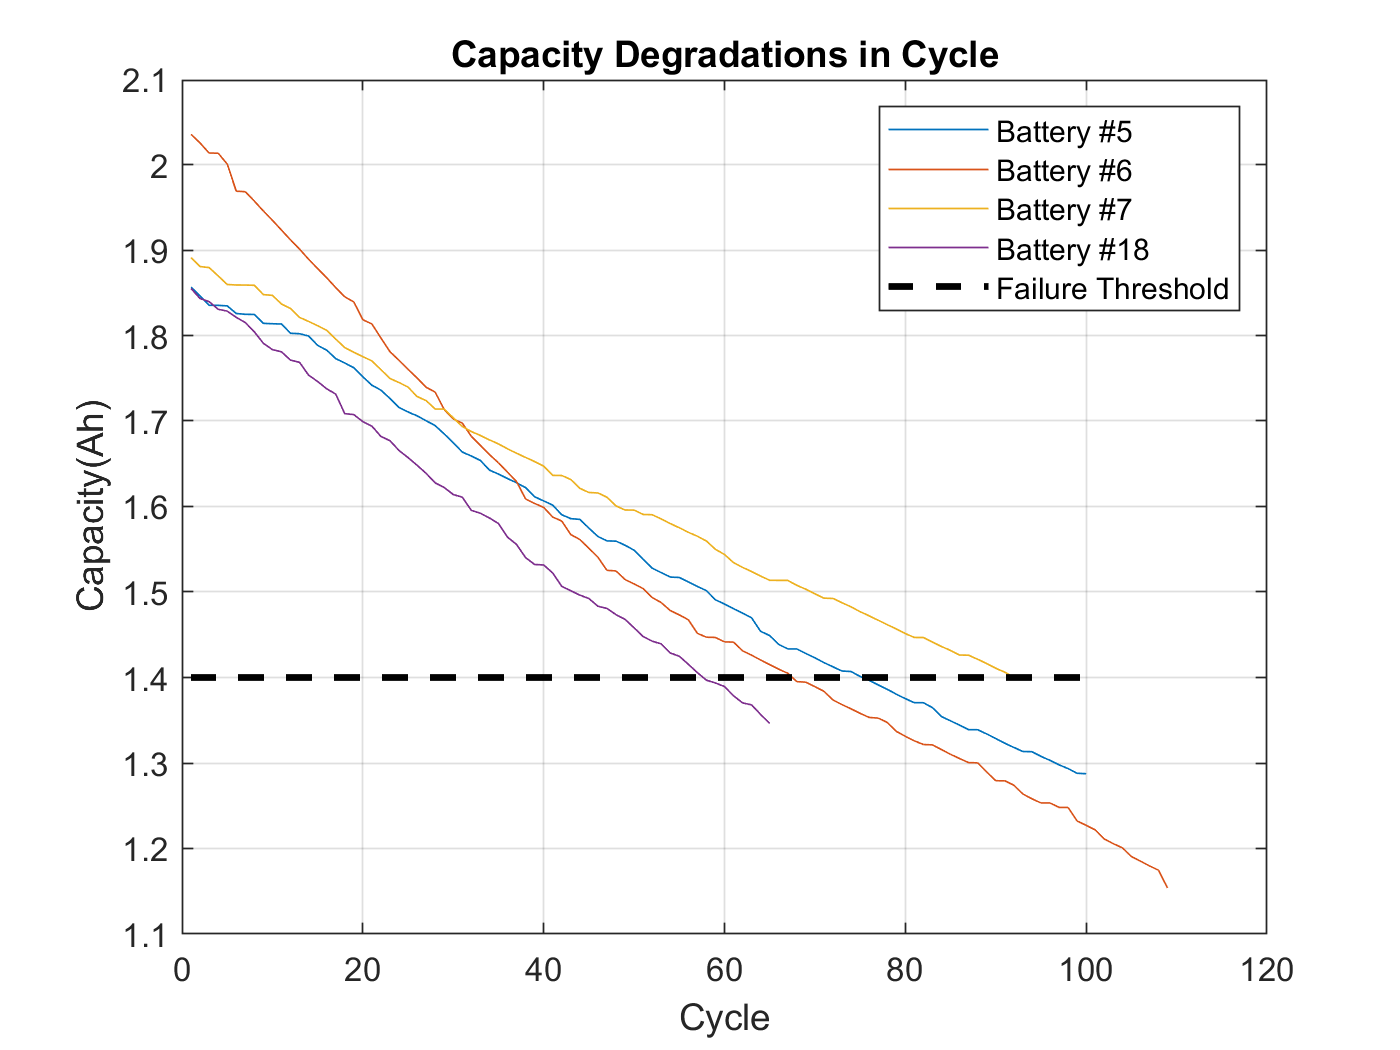

%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

% modify ohm   20 -> 30
result_05(1:30,ohmIdx) = nan;
result_06(1:30,ohmIdx) = nan;
% no gen
% 27 30
% new data set #01 / #02
result_05(27,1)

ans = 1.7003

result_06(30,1)

ans = 1.7024

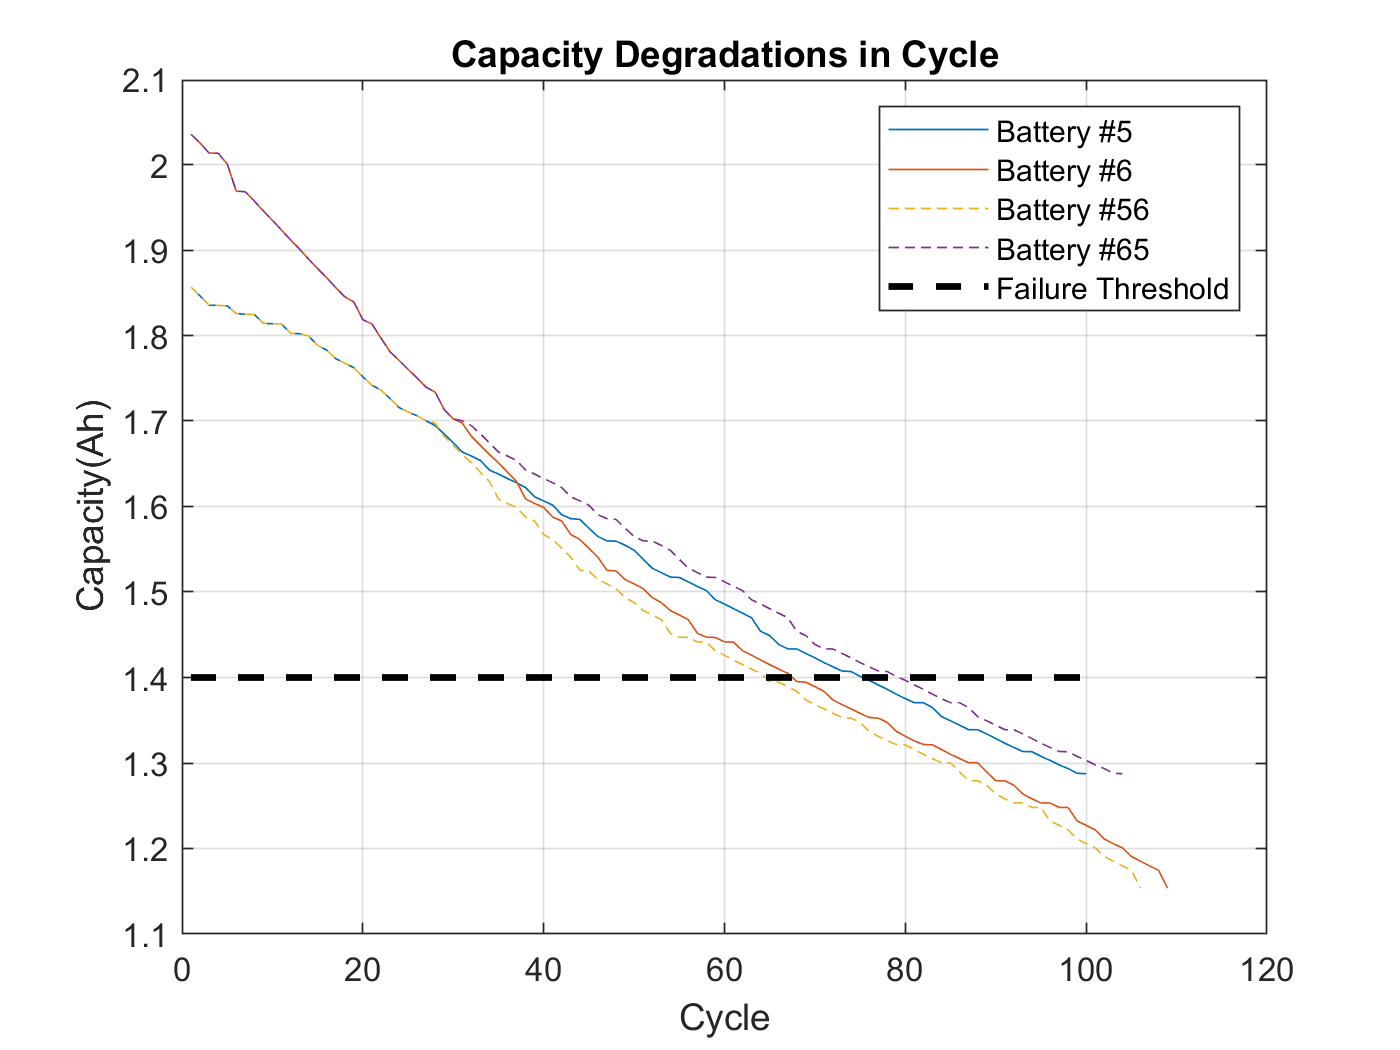


% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:27,:) ; result_06(31:end,:) ]; % 30 -> 31
result_06_05 = [ result_06(1:30,:) ; result_05(27:end,:) ];
result_05_06_patten_change = [27 31];
result_06_05_patten_change = [30 27];

result_05_06_all = [ result_05 ; result_06 ];
capacity56 = result_05_06(:,1);
capacity65 = result_06_05(:,1);
capacity_all = result_05_06_all(:,1);

%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity56,'--'), plot(capacity65,'--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #56', 'Battery #65','Failure Threshold')
title('Capacity Degradations in Cycle')

### Multi-Channel charging profiles of V, I, T data

To observe if charging profiles shows battery aging, we need to explore Voltage(V), Current(I) and Temperature(T) path through battery aging.

In below figure, we can observe that there are significant changes in charging profiles of V, I and T as a battery ages.

방전시는 여러 요인에 따라 결과가 달라질 수 있지만 충전시는 동일한 충전 profile 에 따라 동작하므로 충전시 데이타를 이용하는 것이 좋다.

충전시 최대전압에 도달하기까지의 시간 ( CC가 끝나는 시간) 이나 최대 온도에 도달하는 신호가 index 가 될 수 있다.

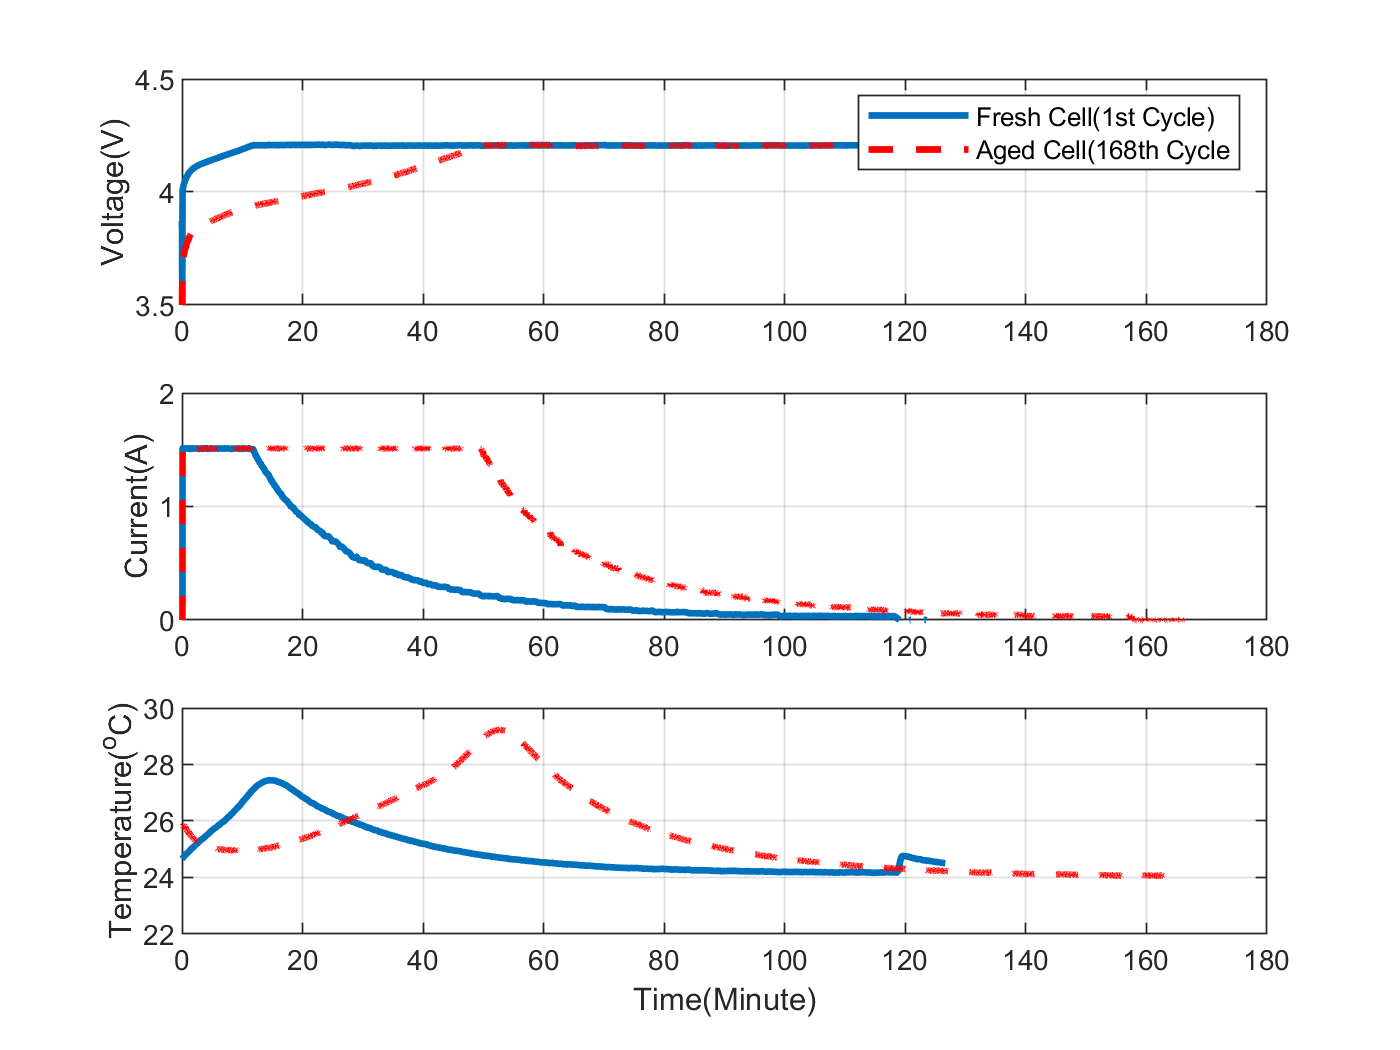


% charge cycle
% time start from 0 sec - vector
% Time:			Time vector for the cycle (secs)
% divide 1sec by 60 => change to minute based

%%%
%Charging 
%constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
%constant voltage (CV) mode until the charge current dropped to 20mA. 

%Voltage_measured: Battery terminal voltage (Volts)
%Current_measured: Battery output current (Amps)
%Temperature_measured: Battery temperature (degree C)
%Current_charge: Current measured at charger (Amps)
%Voltage_charge: Voltage measured at charger (Volts)
%Time: Time vector for the cycle (secs)
%%%

FTime = B0005.cycle(1).data.Time/60;
FreshCell_V = B0005.cycle(1).data.Voltage_measured;
FreshCell_I = B0005.cycle(1).data.Current_measured;
FreshCell_T = B0005.cycle(1).data.Temperature_measured;

ATime = B0005.cycle(168).data.Time/60;
AgedCell_V = B0005.cycle(168).data.Voltage_measured;
AgedCell_I = B0005.cycle(168).data.Current_measured;
AgedCell_T = B0005.cycle(168).data.Temperature_measured;

figure(1)
subplot(311)
plot(FTime, FreshCell_V, 'linewidth', 2), hold on, plot(ATime, AgedCell_V, 'r--','linewidth', 2)
hold off, legend('Fresh Cell(1st Cycle)', 'Aged Cell(168th Cycle'), ylabel('Voltage(V)')
ylim([3.5 4.5]), grid on
subplot(312)
plot(FTime, FreshCell_I, 'linewidth', 2), hold on, plot(ATime, AgedCell_I, 'r--', 'linewidth', 2)
hold off, ylabel('Current(A)'), ylim([0 2]), grid on
subplot(313)
plot(FTime, FreshCell_T, 'linewidth', 2), hold on, plot(ATime, AgedCell_T, 'r--', 'linewidth', 2)
hold off, ylabel('Temperature(^oC)'), ylim([22 30]), grid on, xlabel Time(Minute)

Age (Cycle number) 가 증가함에 따라 floating voltage 까지 충전하는데 시간이 더 걸린다 => 내부 저항의 증가 

floating voltage 이후에는 CV 로 충전으로 변경하는데 이때의 온도가 가장 높다. Age 가 증가함에 따라서 최고 온도 증가.

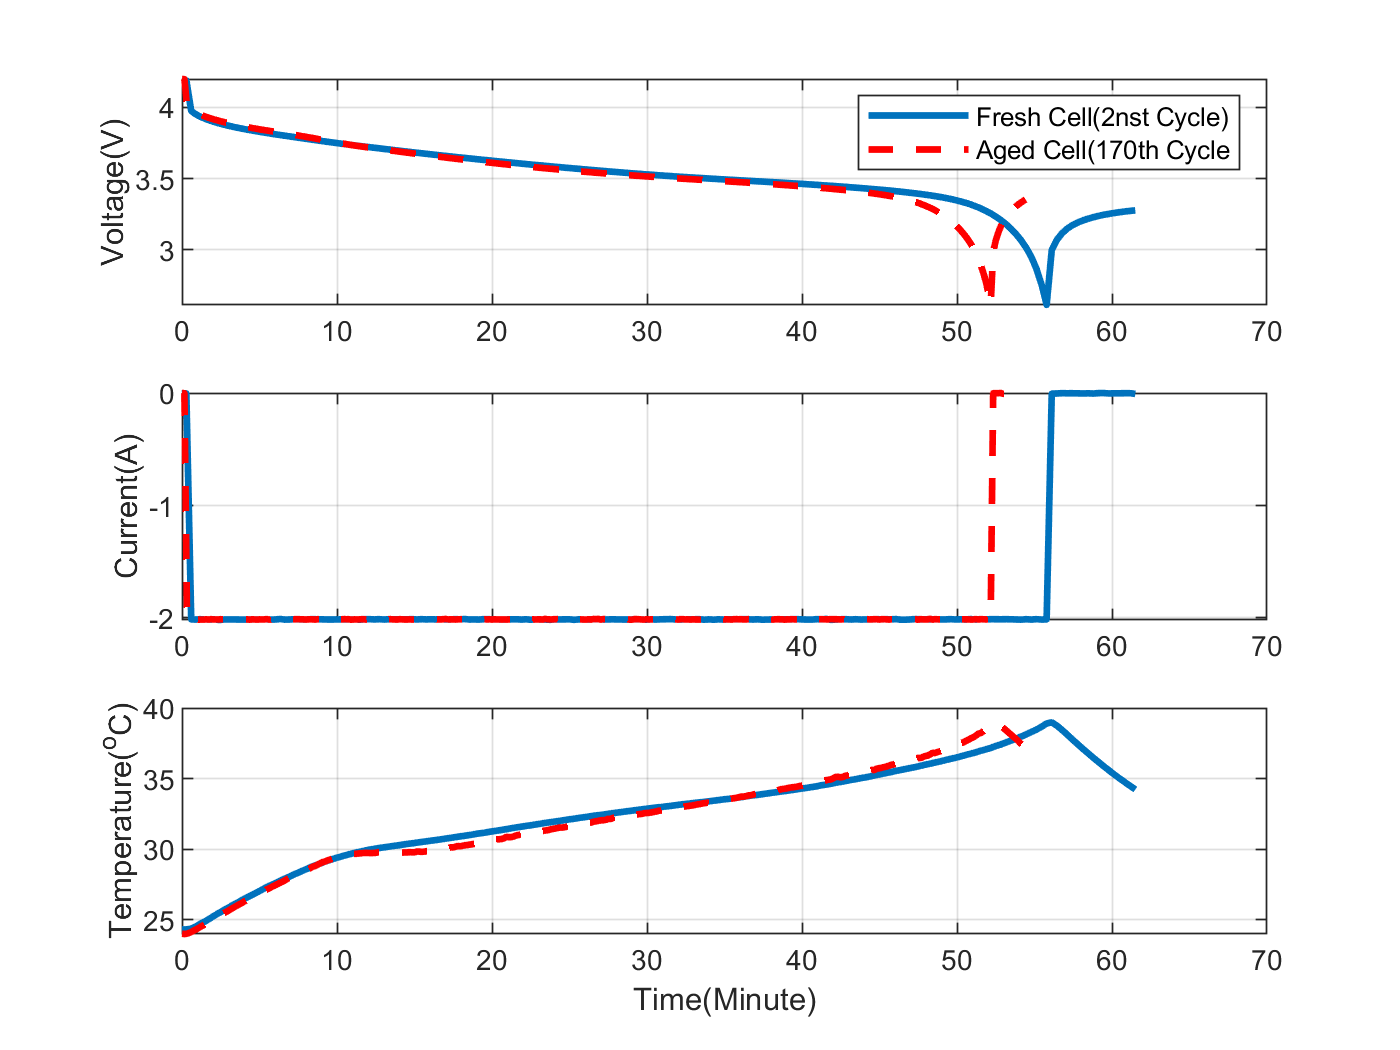


%%%%%% DisCharge

%Discharge
%constant current (CC) level of 2A 
%until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
BAT1 = B0005;
FDischargeTime = BAT1.cycle(2).data.Time/60;
FreshCellDischarge_V = BAT1.cycle(2).data.Voltage_measured;
FreshCellDischarge_I = BAT1.cycle(2).data.Current_measured;
FreshCellDischarge_T = BAT1.cycle(2).data.Temperature_measured;
FreshCellDischargeLoad_V = BAT1.cycle(2).data.Voltage_load;
FreshCellDischargeLoad_I = BAT1.cycle(2).data.Current_load;

ADiscargeTime = BAT1.cycle(170).data.Time/60;
AgedCellDischarge_V = BAT1.cycle(170).data.Voltage_measured;
AgedCellDischarge_I = BAT1.cycle(170).data.Current_measured;
AgedCellDischarge_T = BAT1.cycle(170).data.Temperature_measured;
AgedCellDischargeLoad_V = BAT1.cycle(170).data.Voltage_load;
AgedCellDischargeLoad_I = BAT1.cycle(170).data.Current_load;

%Voltage_measured: Battery terminal voltage (Volts)
%Current_measured: Battery output current (Amps)
%Temperature_measured: Battery temperature (degree C)
%Current_charge: Current measured at load (Amps)
%Voltage_charge: Voltage measured at load (Volts)
%Time: Time vector for the cycle (secs)
%Capacity: Battery capacity (Ahr) for discharge till 2.7V


figure
subplot(311)
plot(FDischargeTime, FreshCellDischarge_V, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischarge_V, 'r--','linewidth', 2)
hold off, legend('Fresh Cell(2nst Cycle)', 'Aged Cell(170th Cycle'), ylabel('Voltage(V)')
%ylim([3.5 4.5]), 
grid on

subplot(312)
plot(FDischargeTime, FreshCellDischarge_I, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischarge_I, 'r--', 'linewidth', 2)
hold off, ylabel('Current(A)'), grid on
% discharge till 2.7V   마이너스 값은 방전 의미
subplot(313)
plot(FDischargeTime, FreshCellDischarge_T, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischarge_T, 'r--', 'linewidth', 2)
hold off, ylabel('Temperature(^oC)'), 
%ylim([22 30]), 
grid on, xlabel Time(Minute)

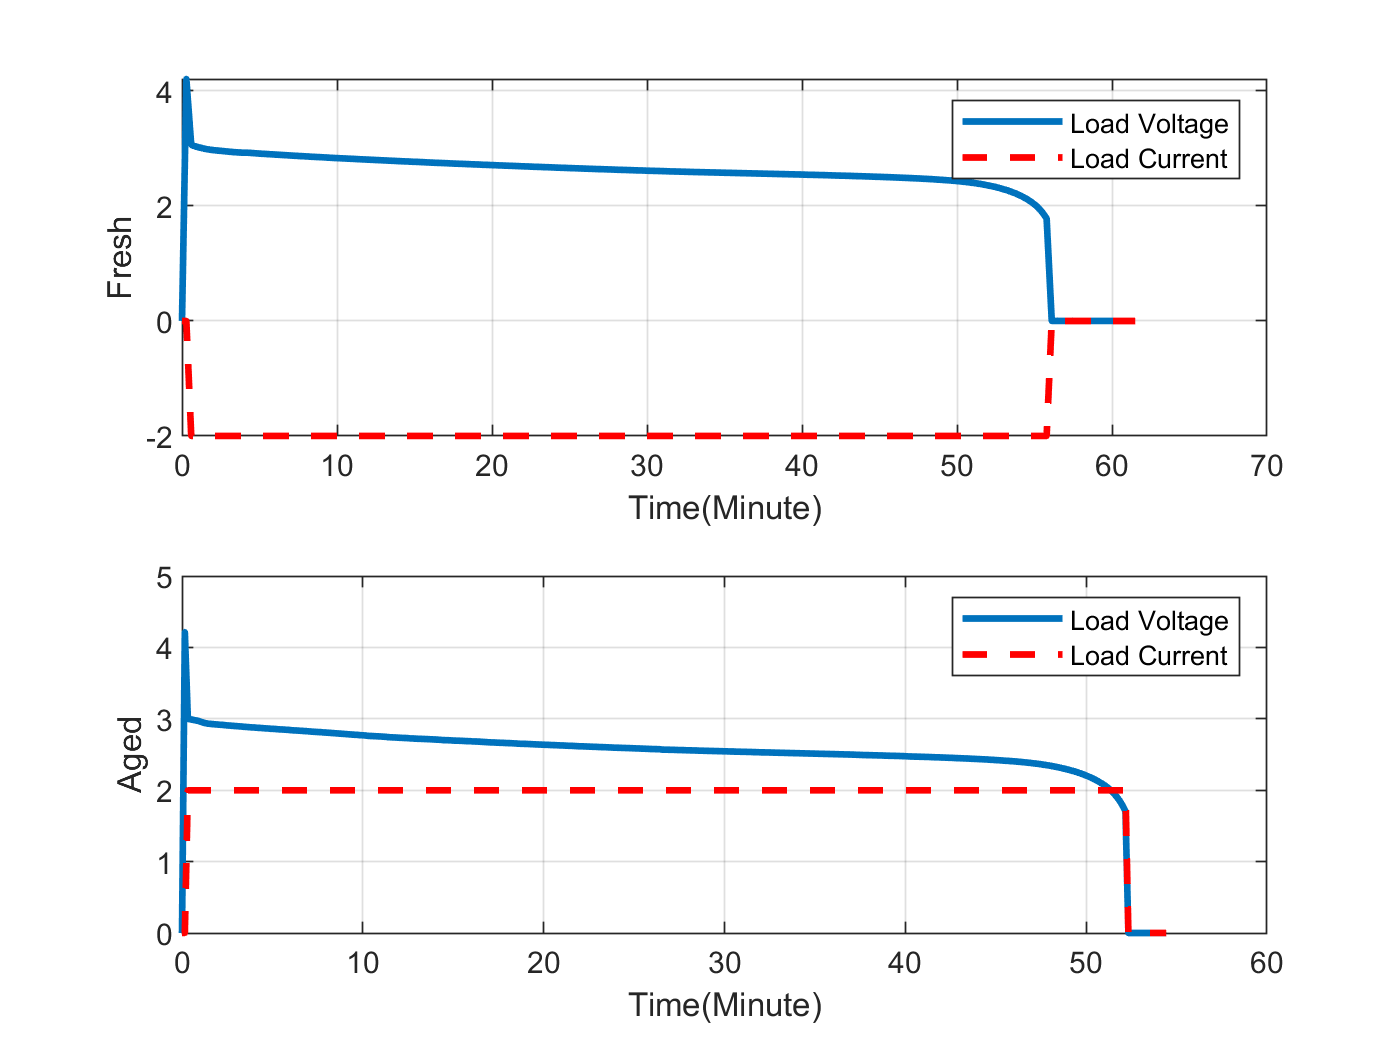


figure
subplot(211)
plot(FDischargeTime, FreshCellDischargeLoad_V, 'linewidth', 2), hold on, plot(FDischargeTime, FreshCellDischargeLoad_I, 'r--', 'linewidth', 2)
hold off, ylabel('Fresh'),legend('Load Voltage','Load Current'), grid on, xlabel Time(Minute)
% 충전기에 표시되는 전압 - CC 이후에 CV  
subplot(212)
plot(ADiscargeTime, AgedCellDischargeLoad_V, 'linewidth', 2), hold on, plot(ADiscargeTime, AgedCellDischargeLoad_I, 'r--', 'linewidth', 2)
hold off, ylabel('Aged'),legend('Load Voltage','Load Current'), grid on, xlabel Time(Minute)


% FTime 과 ATime의 크기는 다르다.
size(BAT1.cycle(1).data.Voltage_measured,2)
size(BAT1.cycle(168).data.Voltage_measured,2)
size(BAT1.cycle)
size(BAT1.cycle,1)
size(BAT1.cycle,2)



### 방전 전압

%%%%%%%%%%%%%%% discharge
figure
%newcolors = {'#F00','#F80','#FF0','#0B0','#00F','#50F','#A0F'};
%colororder(newcolors)

hold on
items = size(B0005.cycle,2)
%marker = ['-','--',':','-.','-o','--o',':o','-.o','+',"*"]

for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state - B0005")
%xlim([0 5])
%ylim([3.5 4.25])
%ylim([3.9 4])
grid on
figure
hold on
items = size(B0006.cycle,2)
for i=1:items
    if isequal(B0006.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0006.cycle(i).data.Time/60,B0006.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state - B0006")
grid on

figure
hold on
items = size(B0007.cycle,2)
for i=1:items
    if isequal(B0007.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0007.cycle(i).data.Time/60,B0007.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state - B0007")
grid on

figure
hold on
items = size(B0018.cycle,2)
for i=1:items
    if isequal(B0018.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60,B0018.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state - B0018")
grid on
figure
hold on
items = size(B0033.cycle,2)
for i=1:items
    if isequal(B0033.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0033.cycle(i).data.Time/60,B0033.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state - B0033")
grid on

figure
hold on
items = size(B0034.cycle,2)
for i=1:items
    if isequal(B0034.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0034.cycle(i).data.Time/60,B0034.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state - B0034")
grid on

figure
hold on
items = size(B0036.cycle,2)
for i=1:items
    if isequal(B0036.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0036.cycle(i).data.Time/60,B0036.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state - B0036")
grid on



discVoltageIndex = 10
discVoltage5 = extract_discharge_voltage_by_index(B0005,discVoltageIndex);
discVoltage6 = extract_discharge_voltage_by_index(B0006,discVoltageIndex);
discVoltage7 = extract_discharge_voltage_by_index(B0007,discVoltageIndex);
figure
plot(discVoltage5), hold on, plot(discVoltage6), plot(discVoltage7)
hold off, grid on
xlabel Cycle, ylabel('Discharge Voltage(Ah)')
% ,num2str(discVoltageIndex))
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Discharge Voltage in Cycle (index = 10)')


### 내부저항

impedance the fields are: 

Sense_current: Current in sense branch (Amps) 

Battery_current: Current in battery branch (Amps) 

Current_ratio: Ratio of the above currents 

Battery_impedance: Battery impedance (Ohms) computed from raw data 

Rectified_impedance: Calibrated and smoothed battery impedance(Ohms) 

**Re: Estimated electrolyte resistance(Ohms) <= ohm 저항 = 수명과 관련 **

Rct: Estimated charge transfer resistance(Ohms) <= 충전 상태와 관련 

비슷한 실험방법으로 측정해 보았다.

뒤쪽으로 선형성을 보이나 앞쪽에서 비선형성이 보여서 사용하기는 어려울 것 같다.

%%%%%%%%%%%%%%% calculate ohm by Voltage and current 

items = size(B0005.cycle,2)
ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        deltaV = B0005.cycle(i).data.Voltage_measured(start_index) -  B0005.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0005.cycle(i).data.Time(measure_index) - B0005.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0005.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0005.cycle(i).data.Time(measure_index) ;
        
        %B0005.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm5 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #5 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on


items = size(B0006.cycle,2)
ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(B0006.cycle(i).type, 'discharge')
        deltaV = B0006.cycle(i).data.Voltage_measured(start_index) -  B0006.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0006.cycle(i).data.Time(measure_index) - B0006.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0006.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0006.cycle(i).data.Time(measure_index) ;
        
        %B0006.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm6 = ohm;
figure
plot(ohm)


title("Register measured by Voltage dop #6 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

items = size(B0007.cycle,2)
ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(B0007.cycle(i).type, 'discharge')
        deltaV = B0007.cycle(i).data.Voltage_measured(start_index) -  B0007.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0007.cycle(i).data.Time(measure_index) - B0007.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0007.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0007.cycle(i).data.Time(measure_index) ;
        
        %B0007.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm7 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #7 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

items = size(B0018.cycle,2)
ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(B0018.cycle(i).type, 'discharge')
        deltaV = B0018.cycle(i).data.Voltage_measured(start_index) -  B0018.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0018.cycle(i).data.Time(measure_index) - B0018.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0018.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0018.cycle(i).data.Time(measure_index) ;
        
        %B0018.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm18 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #18 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on


figure
plot(ohm5), hold on,plot(ohm6),plot(ohm7),plot(ohm18)
legend('5','6','7','18')


NASA 데이타에서 EIS 로 측정된 데이타를 사용하는 경우

실제 데이타가 선형이 아니라서 바로 이용하기는 힘들것 같다.

테스트가 잘못된건지 아무래도 모르겠다.

따라서 내부저항을 확인하기 위해서는 보다 선형적인 다른 dataset 을 찾아야 할 것 같다.

items = size(B0033.cycle,2)
ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(B0033.cycle(i).type, 'discharge')
        deltaV = B0033.cycle(i).data.Voltage_measured(start_index) -  B0033.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0033.cycle(i).data.Time(measure_index) - B0033.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0033.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0033.cycle(i).data.Time(measure_index) ;
        
        %B0033.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm33 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #34- discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

items = size(B0034.cycle,2)
ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(B0034.cycle(i).type, 'discharge')
        deltaV = B0034.cycle(i).data.Voltage_measured(start_index) -  B0034.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0034.cycle(i).data.Time(measure_index) - B0034.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0034.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0034.cycle(i).data.Time(measure_index) ;
        
        %B0034.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm34 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #34 - discharge state")
% 앞부분이 이상한 데이타가 있다
grid on

items = size(B0036.cycle,2)
ohm_index=1;
deltaVoltages = [];
ohm = [];
Ifirst3 = 2; % 2A CC load
Vfirst3 = 4.2;
indexV = []; 
start_index = 1;
measure_index = 5;
for i=1:items
    if isequal(B0036.cycle(i).type, 'discharge')
        deltaV = B0036.cycle(i).data.Voltage_measured(start_index) -  B0036.cycle(i).data.Voltage_measured(measure_index);
        deltaT = B0036.cycle(i).data.Time(measure_index) - B0036.cycle(i).data.Time(start_index);
        
        % deltaV = Vfirst3 -  B0036.cycle(i).data.Voltage_measured(measure_index);
        % deltaT = B0036.cycle(i).data.Time(measure_index) ;
        
        %B0036.cycle(i).data.Voltage_measured(1)
        deltaVoltages(ohm_index) =  deltaV;
        ohm(ohm_index) = deltaV / (deltaT * Ifirst3 );
        indexV(ohm_index)=i;
        
        ohm_index=ohm_index+1;
    end
end
ohm36 = ohm;
figure
plot(ohm)

title("Register measured by Voltage dop #36- discharge state")
% 앞부분이 이상한 데이타가 있다
grid on



figure
plot(ohm33), hold on,plot(ohm34),plot(ohm36)
legend('33','34','36')




%%%%%%% Re 

re5 = extract_impedance_re(B0005);
re6 = extract_impedance_re(B0006);
re7 = extract_impedance_re(B0007);
figure
plot(re5), hold on, plot(re6), plot(re7)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance  in Cycle')


%%%%%%% Re - charge
re5c = extract_impedance_re_charge(B0005);
re6c = extract_impedance_re_charge(B0006);
re7c = extract_impedance_re_charge(B0007);
figure
plot(re5c), hold on, plot(re6c), plot(re7c)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')


%%%%%%% Re - discharge

re5d = extract_impedance_re_discharge(B0005);
re6d = extract_impedance_re_discharge(B0006);
re7d = extract_impedance_re_discharge(B0007);
figure
plot(re5d), hold on, plot(re6d), plot(re7d)
hold off, grid on
xlabel Cycle, ylabel Impedance(Ohm)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Estimated electrolyte resistance in Cycle')

## 온도 / 전압 / 전류

figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured - charge state")
grid on

#### 충전전압


figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured B0005 - charge state")
grid on

#### 충전전류

figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0005 - charge state")
ylim([-0.5 2])
grid on
figure
hold on
items = size(B0006.cycle,2);
for i=1:items
    if isequal(B0006.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0006.cycle(i).data.Time/60,B0006.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0006 - charge state")
grid on

figure
hold on
items = size(B0007.cycle,2);
for i=1:items
    if isequal(B0007.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0007.cycle(i).data.Time/60,B0007.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0007 - charge state")
grid on

figure
hold on
items = size(B0018.cycle,2);
for i=1:items
    if isequal(B0018.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60,B0018.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0018 - charge state")
grid on


figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured - discharge state")
grid on
figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Voltage_measured)
        end
    end
end
hold off 
title("Voltage measured - discharge state")
grid on

figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0005- discharge state")
grid on

figure
hold on
items = size(B0006.cycle,2);
for i=1:items
    if isequal(B0006.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0006.cycle(i).data.Time/60,B0006.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0006 - discharge state")
grid on

figure
hold on
items = size(B0007.cycle,2);
for i=1:items
    if isequal(B0007.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0007.cycle(i).data.Time/60,B0007.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0007 - discharge state")
grid on

figure
hold on
items = size(B0018.cycle,2);
for i=1:items
    if isequal(B0018.cycle(i).type, 'discharge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60,B0018.cycle(i).data.Current_measured)
        end
    end
end
hold off 
title("Current measured B0018 - discharge state")
grid on



## 온도와 capacity의 관계

charge 사이클에서 최대온도와 capacity의 관계

[cap,maxTemp,maxTimeDelta] = extract_temperature_max_time_charge_cycle_v1(B0005);

figure

plot(cap), hold on, 
yyaxis right
plot(maxTemp) %, plot(maxTimeDelta)
%plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle
legend('Capacity', 'Max Temp')%, 'Time to Max Temp')
title('Capacity Degradations and Max Temperate in Charge Cycle')



charge 사이클에서 최대온도까지 올라가는 시간과 capacity의 관계


figure
plot(cap), hold on, 
yyaxis right
plot(maxTimeDelta) %, plot(maxTimeDelta)
%plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle
legend('Capacity', 'Time to Max Temp')%, 'Time to Max Temp')
title('Capacity Degradations and Time to Max Temp in Charge Cycle')


측정도중 이상한 값들이 존재한다.

충전시작시 (시간 0) 에서 온도가 충전 CC 완료시의 온도보다 높은 데이타가 존재한다.

따라서 그냥 max 함수를 사용하면 안되고 islocalmax 함수를 사용해야 한다.



figure
findpeaks(B0005.cycle(1).data.Temperature_measured)
findpeaks(B0005.cycle(3).data.Temperature_measured)
findpeaks(B0005.cycle(5).data.Temperature_measured)
findpeaks(B0005.cycle(7).data.Temperature_measured)
findpeaks(B0005.cycle(9).data.Temperature_measured)
%[pks,loc] = findpeaks(B0005.cycle(1).data.Temperature_measured)
figure
t = 1: length(B0005.cycle(9).data.Temperature_measured);
%lm = islocalmax(B0005.cycle(9).data.Temperature_measured);
lm = islocalmax(B0005.cycle(9).data.Temperature_measured,'MinProminence',2);

plot(t,B0005.cycle(9).data.Temperature_measured)
hold on
%yyaxis right
plot(t(lm),B0005.cycle(9).data.Temperature_measured(lm),'r*')
lm 


figure
t = 1: length(B0005.cycle(1).data.Temperature_measured);
%lm = islocalmax(B0005.cycle(9).data.Temperature_measured);
boolIndex = islocalmax(B0005.cycle(1).data.Temperature_measured,'MinProminence',2);

plot(t,B0005.cycle(1).data.Temperature_measured)
hold on
%yyaxis right
plot(t(boolIndex),B0005.cycle(1).data.Temperature_measured(boolIndex),'r*')


boolIndex
% https://kr.mathworks.com/matlabcentral/answers/155348-how-do-you-find-the-index-of-the-first-true-value-in-a-logical-vector
V1 = find(boolIndex, 1, 'first')
B0005.cycle(1).data.Temperature_measured(find(boolIndex, 1, 'first'))


온도에서는 최고온도까지 올라가는 것이 Capacity 와 관계가 매우 높다. 

단순히 최고 온도는 상관관계가 없다.

Abnormal 까지 체크하는 함수 

나중에 abnormal 한 것은 interpolation 하자.

[cap,maxTemp,maxTimeDelta,abnormal] = extract_temperature_max_time_charge_cycle(B0005);

figure

plot(cap), hold on, 
yyaxis right
plot(maxTemp) %, plot(maxTimeDelta)
%plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle
legend('Capacity', 'Max Temp')%, 'Time to Max Temp')
title('Capacity Degradations and Max Temperate in Charge Cycle')

figure
plot(cap), hold on, 
yyaxis right
plot(maxTimeDelta) %, plot(maxTimeDelta)
%plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle
legend('Capacity', 'Time to Max Temp')%, 'Time to Max Temp')
title('Capacity Degradations and Time to Max Temp in Charge Cycle')